# Code for Analyzing & Visualizing ICESat-2 ATL06 Elevation Residuals for Wolverine Glacier, Alaska

## Initialize

clear all; close all;
addpath('/users/ellynenderlin/Research/miscellaneous/general-code/','/users/ellynenderlin/Research/miscellaneous/general-code/cmocean/');
addpath('/Users/ellynenderlin/Research/NASA_CryoIdaho/ICESat2-snow-code/');

%make figure folder as necessary
root_path = '/Users/ellynenderlin/Research/NASA_CryoIdaho/'; cd(root_path);
if exist('figures','dir') ~= 7; mkdir('figures'); end
figure_path = [root_path,'figures/'];

%DTM (be sure the path ends in a /)
DTM_path = [root_path,'glaciers/Wolverine/DEMs/'];
DTM_name = 'WG-DEM-timeseries.mat';
DTM_mask = 'WG-DEM-datamask.mat';


%site abbreviation for file names
abbrev = 'WG';

%ICESat-2 product acronym
acronym = 'ATL06';

%csv (be sure the path ends in a /)
csv_path = [root_path,'glaciers/Wolverine/csvs/'];
cd(csv_path);
T = readtable([abbrev,'-ICESat2-',acronym,'-params.csv']);

%load outlines: glacier, catchment, & state
%glacier outline in UTM coords
glims = shaperead([root_path,'glaciers/Wolverine/ROIs/Wolverine-2018-outline-UTM06N.shp']); % load in polygon
S.X = glims.X; S.Y = glims.Y; % note: 2d version of the glims polygon made in QGIS... Matlab's shaperead can't handle a PolygonZ geometry
%catchment outline in UTM coords (or uncomment line 24 to convert to UTM)
catchment = shaperead([root_path,'glaciers/Wolverine/ROIs/WG_catchment_2021.shp']);
[catchx,catchy] = wgs2utm(catchment.Y,catchment.X); clear catchment; catchment.X = catchx; catchment.Y = catchy;
%state outline (coords shouldn't matter)
state = shaperead([root_path,'glaciers/Wolverine/ROIs/Alaska-shapefile.shp']);

%site-specific coregistration information
snowline = 1235; coreg_season = 3; %must know these site-specific parameters

%seasonal colors
% wincolor = [43,131,186]/255;
% sprcolor = [99,99,99]/255;
% sumcolor = [215,25,28]/255;
% falcolor = [253,174,97]/255;
% seas_cmap = [wincolor; sprcolor; sumcolor; falcolor];
seas_cmap = [5,113,176; 202,0,32]/255;
asl_cmap = colormap(gray(5001));

%colorblind-friendly elevation residual colorramp
cblind_colors = [64,0,75; 	118,42,131;	153,112,171;...
    194,165,207;	231,212,232;	247,247,247;	217,240,211;...
    166,219,160;	90,174,97;	27,120,55;	0,68,27]/255;

%day of year info for date conversion
modays = [31 28 31 30 31 30 31 31 30 31 30 31]; cumdays = [0 cumsum(modays(1:end-1))];
leap_modays = [31 29 31 30 31 30 31 31 30 31 30 31]; leap_cumdays = [0 cumsum(leap_modays(1:end-1))];

%trendlines
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Robust = 'Bisquare';
ft1 = fittype('poly1');
ft2 = fittype( 'a*cosd(x+b)+c', 'independent', 'x', 'dependent', 'y' ); 

%letters for subplot labels
alphabet = 'abcdefghijklmnopqrstuvwxyz';

## Load the DEM(s)

%NOTE: Available DEMs
%2020/10/19, 2020/07/28, 2019/09/20, 2018/09/12, 2015/10/18, 2011/07/06, 2008/10/01
%(2008,2015,2018,2020 = WorldView, 2019 = CRREL lidar, 2011=IfSAR)

%load the DEMs
cd_to_DTM = ['cd ',DTM_path]; eval(cd_to_DTM);
load(DTM_name);

%convert spatial reference info (R structure) into x & y vectors
for k = 1:length(Z)
    Z(k).x = Z(k).R.XWorldLimits(1)+0.5*Z(k).R.CellExtentInWorldX:Z(k).R.CellExtentInWorldX:Z(k).R.XWorldLimits(end)-0.5*Z(k).R.CellExtentInWorldX; % get a vector of x coords
    Z(k).y = Z(k).R.YWorldLimits(2)-0.5*Z(k).R.CellExtentInWorldY:-Z(k).R.CellExtentInWorldY:Z(k).R.YWorldLimits(1)+0.5*Z(k).R.CellExtentInWorldY; % get a vector of y coords
    [Z(k).xgrid, Z(k).ygrid] = meshgrid(Z(k).x, Z(k).y); % create grids of each of the x and y coords
end

%load the DEM mask to double-check that data are filtered outside of the smallest DEM's footprint
load_DEMmask = ['load ',DTM_mask]; eval(load_DEMmask);


## Filter Outliers & Apply an Ice Mask

%filter outliers with slopes >3xMAD from the median (Matlab's default outlier filter)
slope_outliers = isoutlier(T.slope);
T.ruggedness(slope_outliers) = NaN;
T.ReferenceElevation(slope_outliers) = NaN;
T.slope(slope_outliers) = NaN;
T.aspect(slope_outliers) = NaN;
T.differences(slope_outliers) = NaN;
clear slope_outliers;
disp('filtered outliers');

filtered outliers



%replace data outside the smallest DEM footprint with NaNs
[mask_xgrid,mask_ygrid] = meshgrid(DEMmask.x,DEMmask.y);
DEMmask.z(DEMmask.z==0) = NaN;
mask = interp2(mask_xgrid,mask_ygrid,DEMmask.z,T.Easting,T.Northing,'nearest');
T.ReferenceElevation(isnan(mask)) = NaN;
T.differences(isnan(mask)) = NaN;
%identify glacierized & non-glacierized data
Tin_ref = inpolygon(T.Easting, T.Northing, S.X, S.Y); % get logical vector (1 = inside of the shape)
Tin = T(Tin_ref == 1, :); Tout = T(Tin_ref == 0, :);
clear mask;

%display stats on data availability
disp(['Number of observation dates = ',num2str(length(unique(T.date(~isnan(T.ReferenceElevation)))))])

Number of observation dates = 18


disp(['Total number of observations = ',num2str(length(T.date(~isnan(T.ReferenceElevation))))])

Total number of observations = 7099


disp(['Number of coregistration observations = ',num2str(length(Tout.date(~isnan(Tout.ReferenceElevation) & Tout.season==coreg_season & Tout.ReferenceElevation < snowline)))])

Number of coregistration observations = 783


## Parse Into Seasons

%parse into seasons
iwin = find(T.season == 1); winT = T(iwin, :);
ispr = find(T.season == 2); sprT = T(ispr, :);
isum = find(T.season == 3); sumT = T(isum, :);
ifal = find(T.season == 4); falT = T(ifal, :);

% get x and y vectors for points in, out
winTx = winT.Easting; winTy=winT.Northing;
sprTx = sprT.Easting; sprTy=sprT.Northing;
sumTx = sumT.Easting; sumTy=sumT.Northing;
falTx = falT.Easting; falTy=falT.Northing;

%create mask
winin_ref = inpolygon(winTx, winTy, S.X, S.Y);
winT.inpolygon = winin_ref; % save as an additional column in the table
sprin_ref = inpolygon(sprTx, sprTy, S.X, S.Y);
sprT.inpolygon = sprin_ref;
sumin_ref = inpolygon(sumTx, sumTy, S.X, S.Y);
sumT.inpolygon = sumin_ref;
falin_ref = inpolygon(falTx, falTy, S.X, S.Y);
falT.inpolygon = falin_ref;

%identify data inside and outside the glacier polygon
winin = winT(winT.inpolygon == 1, :); winout = winT(winT.inpolygon == 0, :);
sprin = sprT(sprT.inpolygon == 1, :); sprout = sprT(sprT.inpolygon == 0, :);
sumin = sumT(sumT.inpolygon == 1, :); sumout = sumT(sumT.inpolygon == 0, :);
falin = falT(falT.inpolygon == 1, :); falout = falT(falT.inpolygon == 0, :);

% write seasonally-partitioned tables
writetable(winT, [csv_path,abbrev,'win.csv']);
writetable(sprT, [csv_path,abbrev,'spr.csv']);
writetable(sumT, [csv_path,abbrev,'sum.csv']);
writetable(falT, [csv_path,abbrev,'fal.csv']);


## Display Basic Statistics

%set-up ranges of each terrain parameter
elev_extremes = isoutlier(Tin.ReferenceElevation);
elev_x = floor(min(Tin.ReferenceElevation(elev_extremes~=1))/10)*10:100:ceil(max(Tin.ReferenceElevation(elev_extremes~=1))/10)*10;
slope_x = 0:5:ceil(max(Tin.slope)/10)*10;
aspect_x = 0:10:360;
% rough_x = 0:2:10; %uncomment here & corresponding lines below if considering a roughness/ruggedness metric
elev_lims = [min(min(Tin.ReferenceElevation)) max(elev_x)];

%vertical biases
fprintf('Bias for coregistration = %4.2f +/- %4.2f m',nanmedian(Tout.VerticalErrors(Tout.season==coreg_season & Tout.ReferenceElevation < snowline)),mad(Tout.VerticalErrors(Tout.season==coreg_season & Tout.ReferenceElevation < snowline),1));

Bias for coregistration = -2.51 +/- 0.88 m

fprintf('Bias for all segments = %4.2f +/- %4.2f m',nanmedian(Tout.VerticalErrors),mad(Tout.VerticalErrors,1));

Bias for all segments = -2.10 +/- 1.34 m


%split data into just snow-on (Oct-Apr) & snow-off (June-Sept) seasons
fprintf('Off-glacier snow-off season = %1.4f +/- %1.4f m',nanmedian(Tout.differences(Tout.season == 3 & Tout.ReferenceElevation < snowline)),mad(Tout.differences(Tout.season == 3 & Tout.ReferenceElevation < snowline),1));

Off-glacier snow-off season = 0.0008 +/- 0.8827 m

fprintf('Glacier snow-off season = %1.4f +/- %1.4f m',nanmedian(Tin.differences(Tin.season == 3)),mad(Tin.differences(Tin.season == 3),1));

Glacier snow-off season = -1.2593 +/- 0.7862 m

fprintf('Off-glacier snow-on season = %1.4f +/- %1.4f m',nanmedian(Tout.differences(Tout.season ~= 3 & Tout.ReferenceElevation < snowline)),mad(Tout.differences(Tout.season ~= 3 & Tout.ReferenceElevation < snowline),1));

Off-glacier snow-on season = 0.6283 +/- 1.4030 m

fprintf('Glacier snow-on season = %1.4f +/- %1.4f m',nanmedian(Tin.differences(Tin.season ~= 3)),mad(Tin.differences(Tin.season ~= 3),1));

Glacier snow-on season = 2.5330 +/- 1.6681 m

## Create Boxplots of Elevation Residuals With Respect To Terrain Parameters

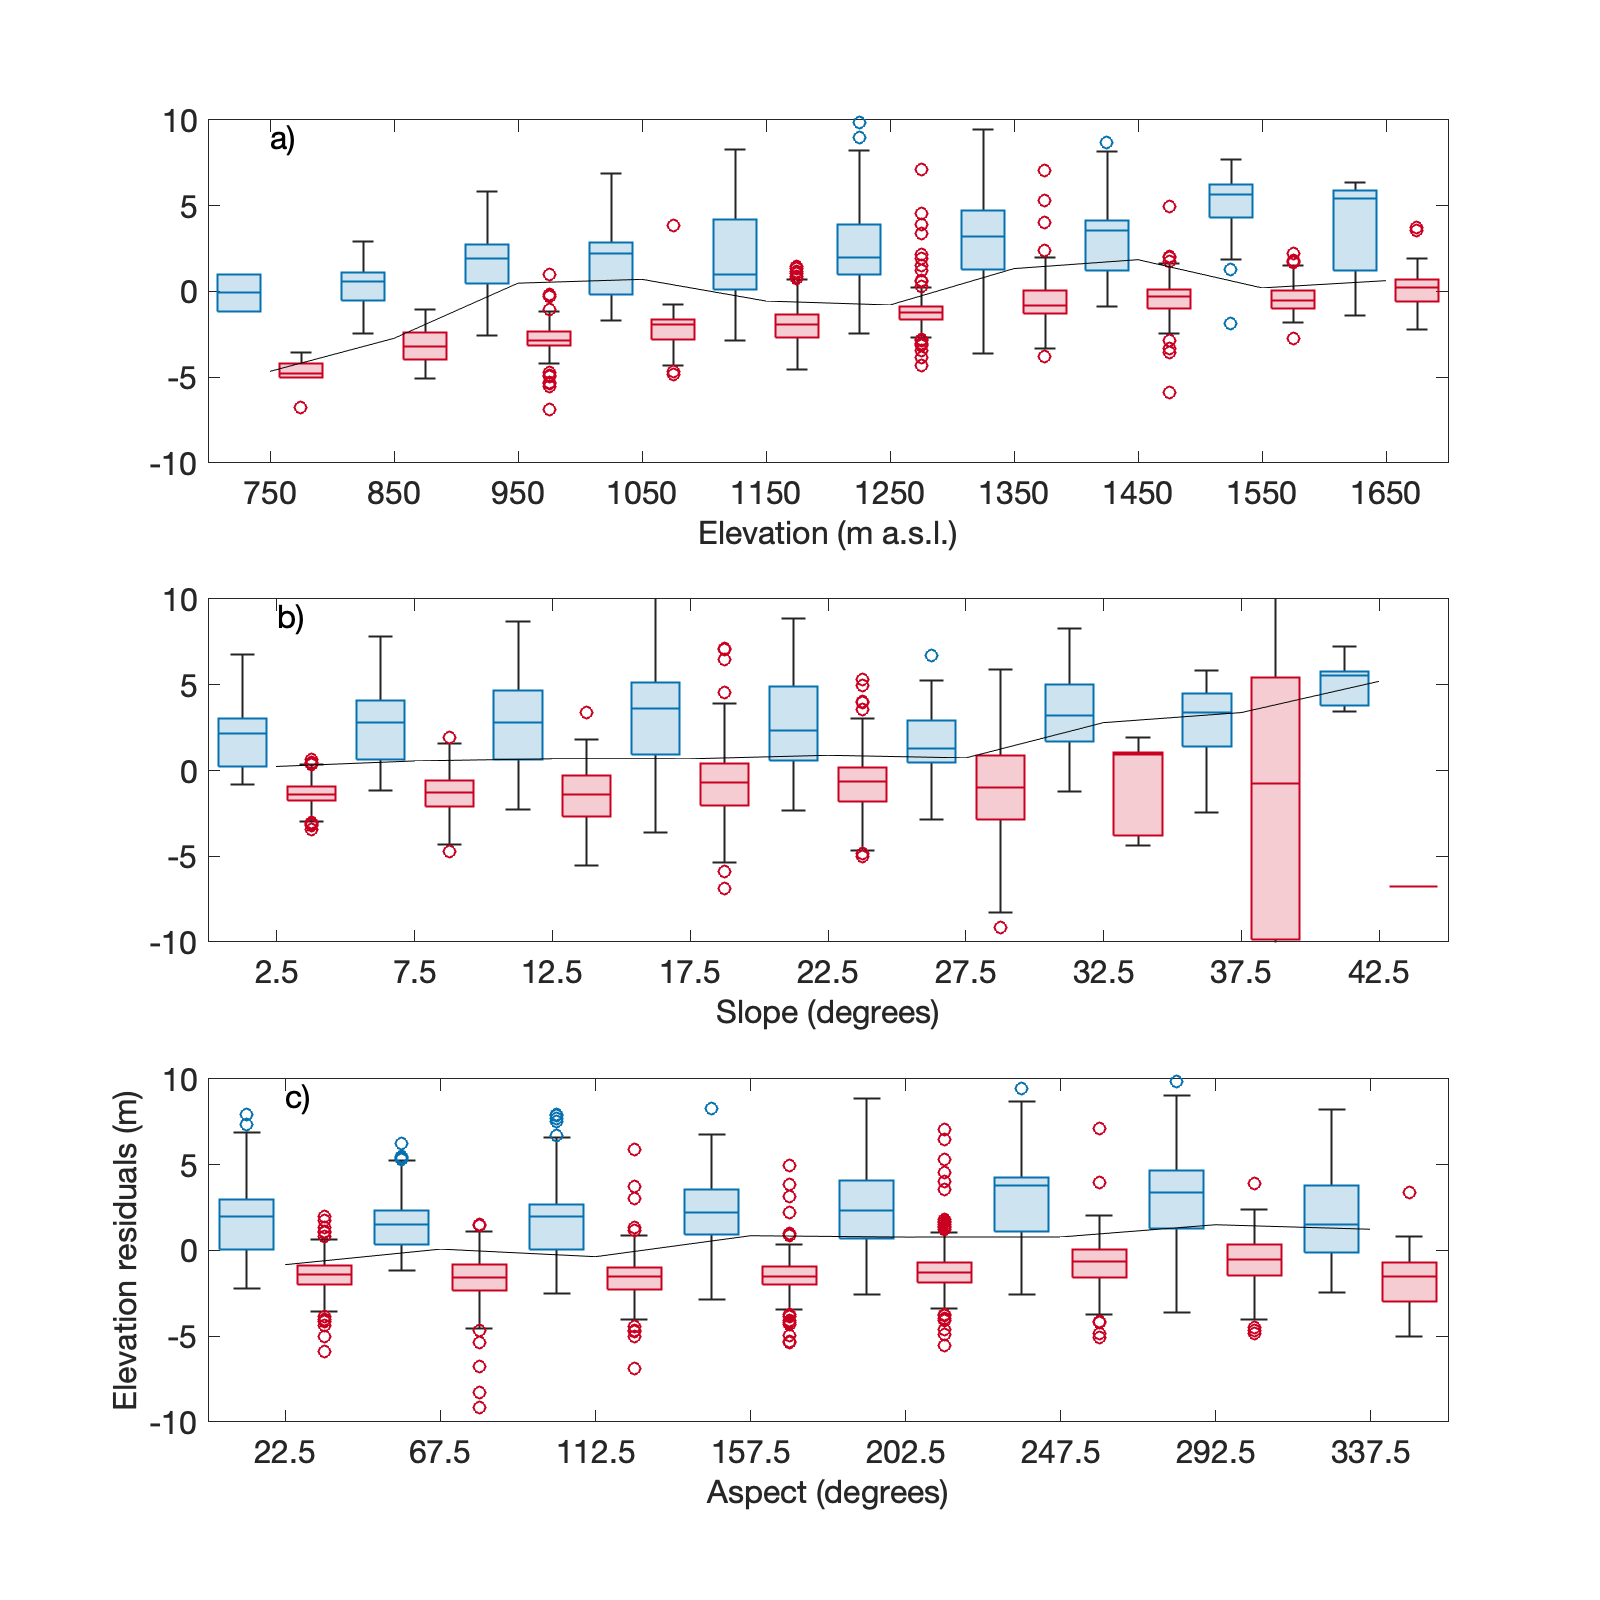

2018.6986 snow-on :


min = 0.38965m, max = 6.2567m, gradient = 0.0048562m/m


2018.6986 snow-off :


min = -2.7879m, max = 0.60403m, gradient = 0.0048368m/m


2019.7205 snow-on :


min = 0.38216m, max = 1.4002m, gradient = -9.7935e-05m/m


2020.7077 snow-on :


min = 0.40284m, max = 3.7114m, gradient = 0.0039729m/m


2020.7077 snow-off :


min = -4.6613m, max = -0.063344m, gradient = 0.0041165m/m


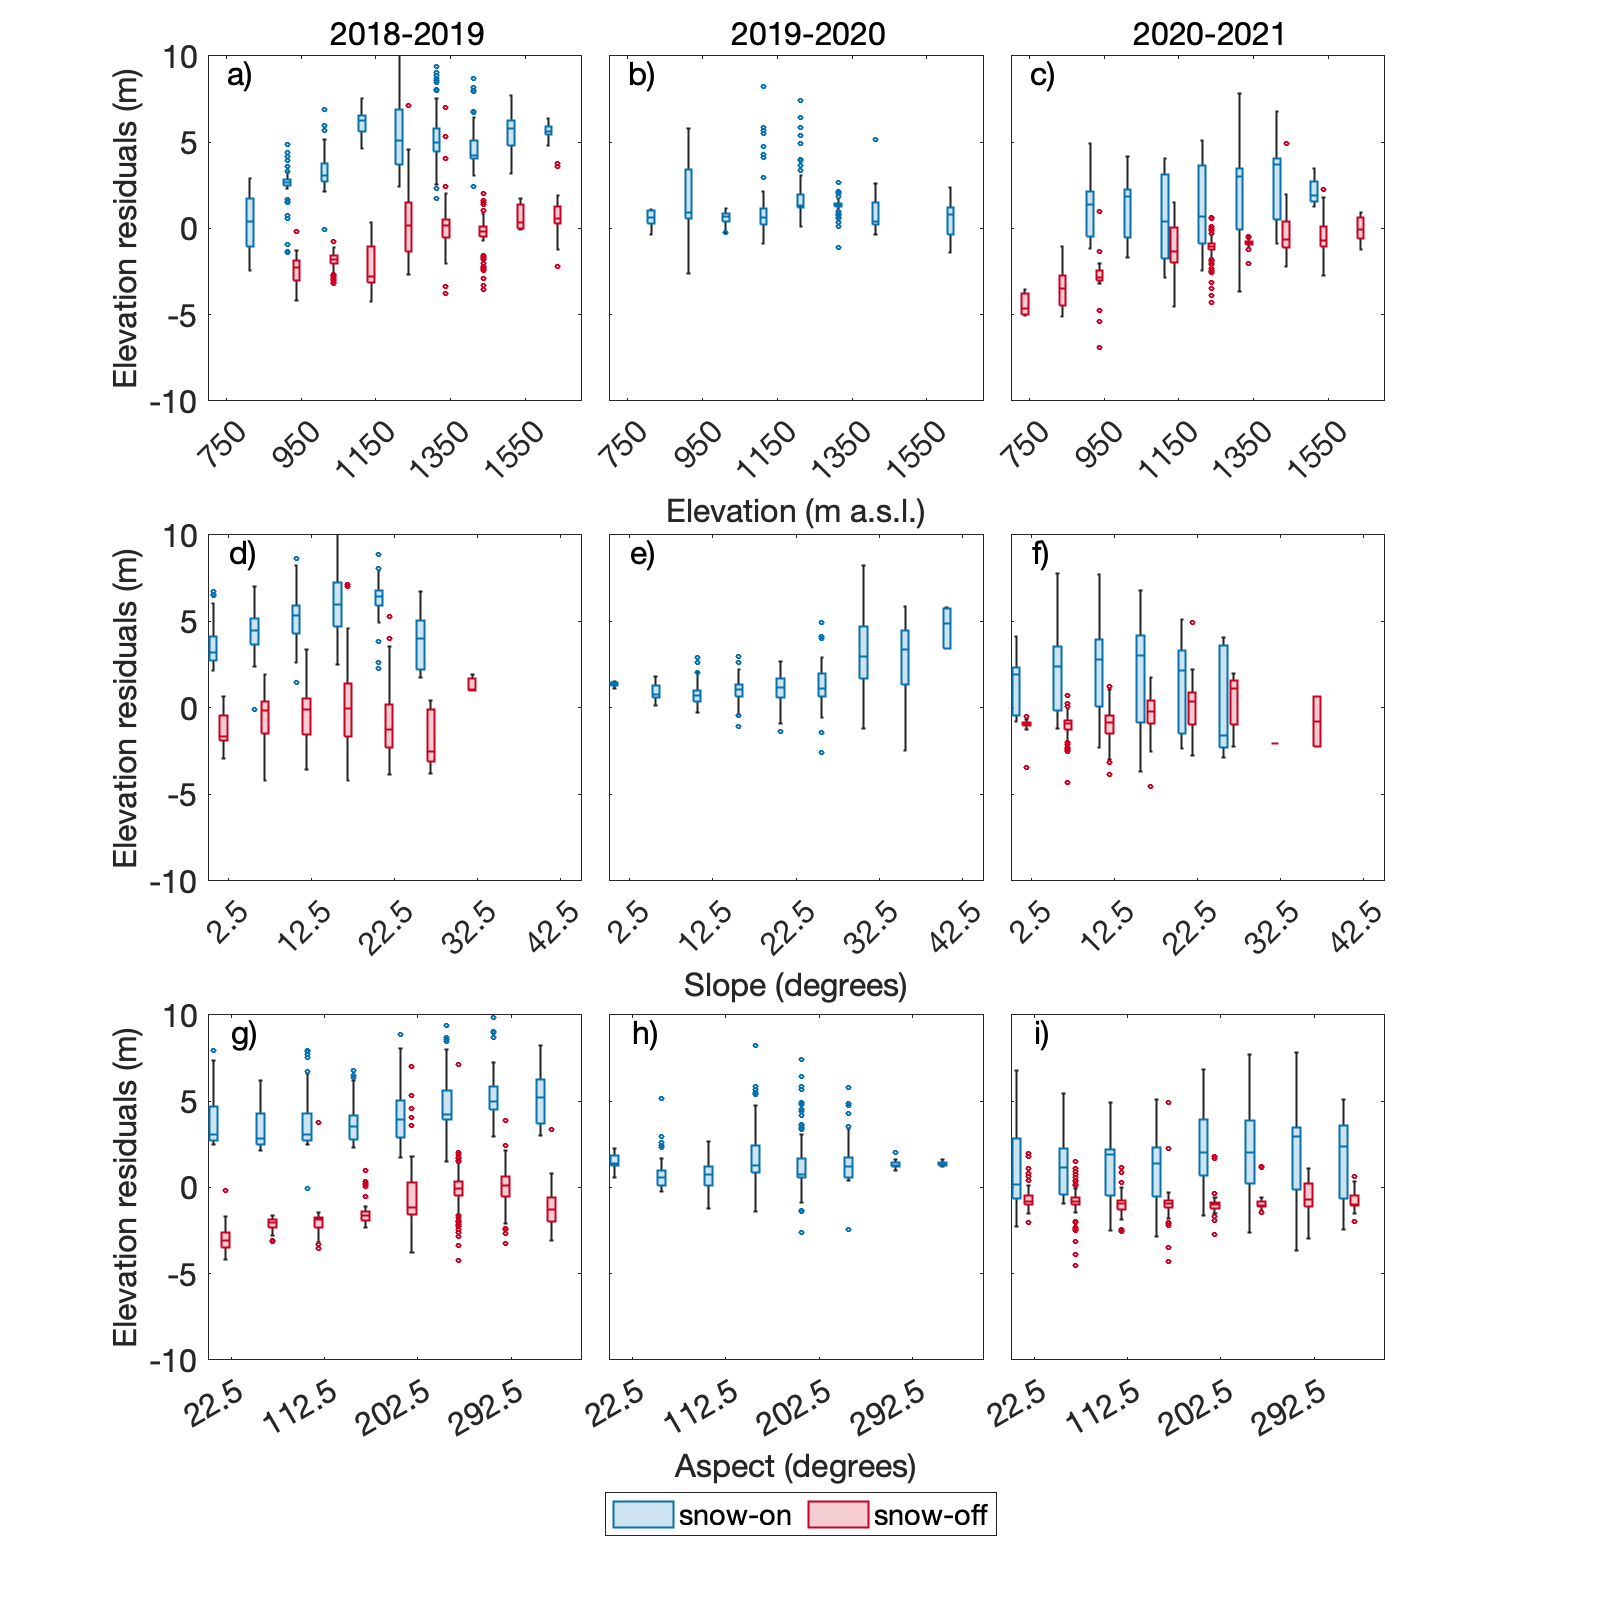

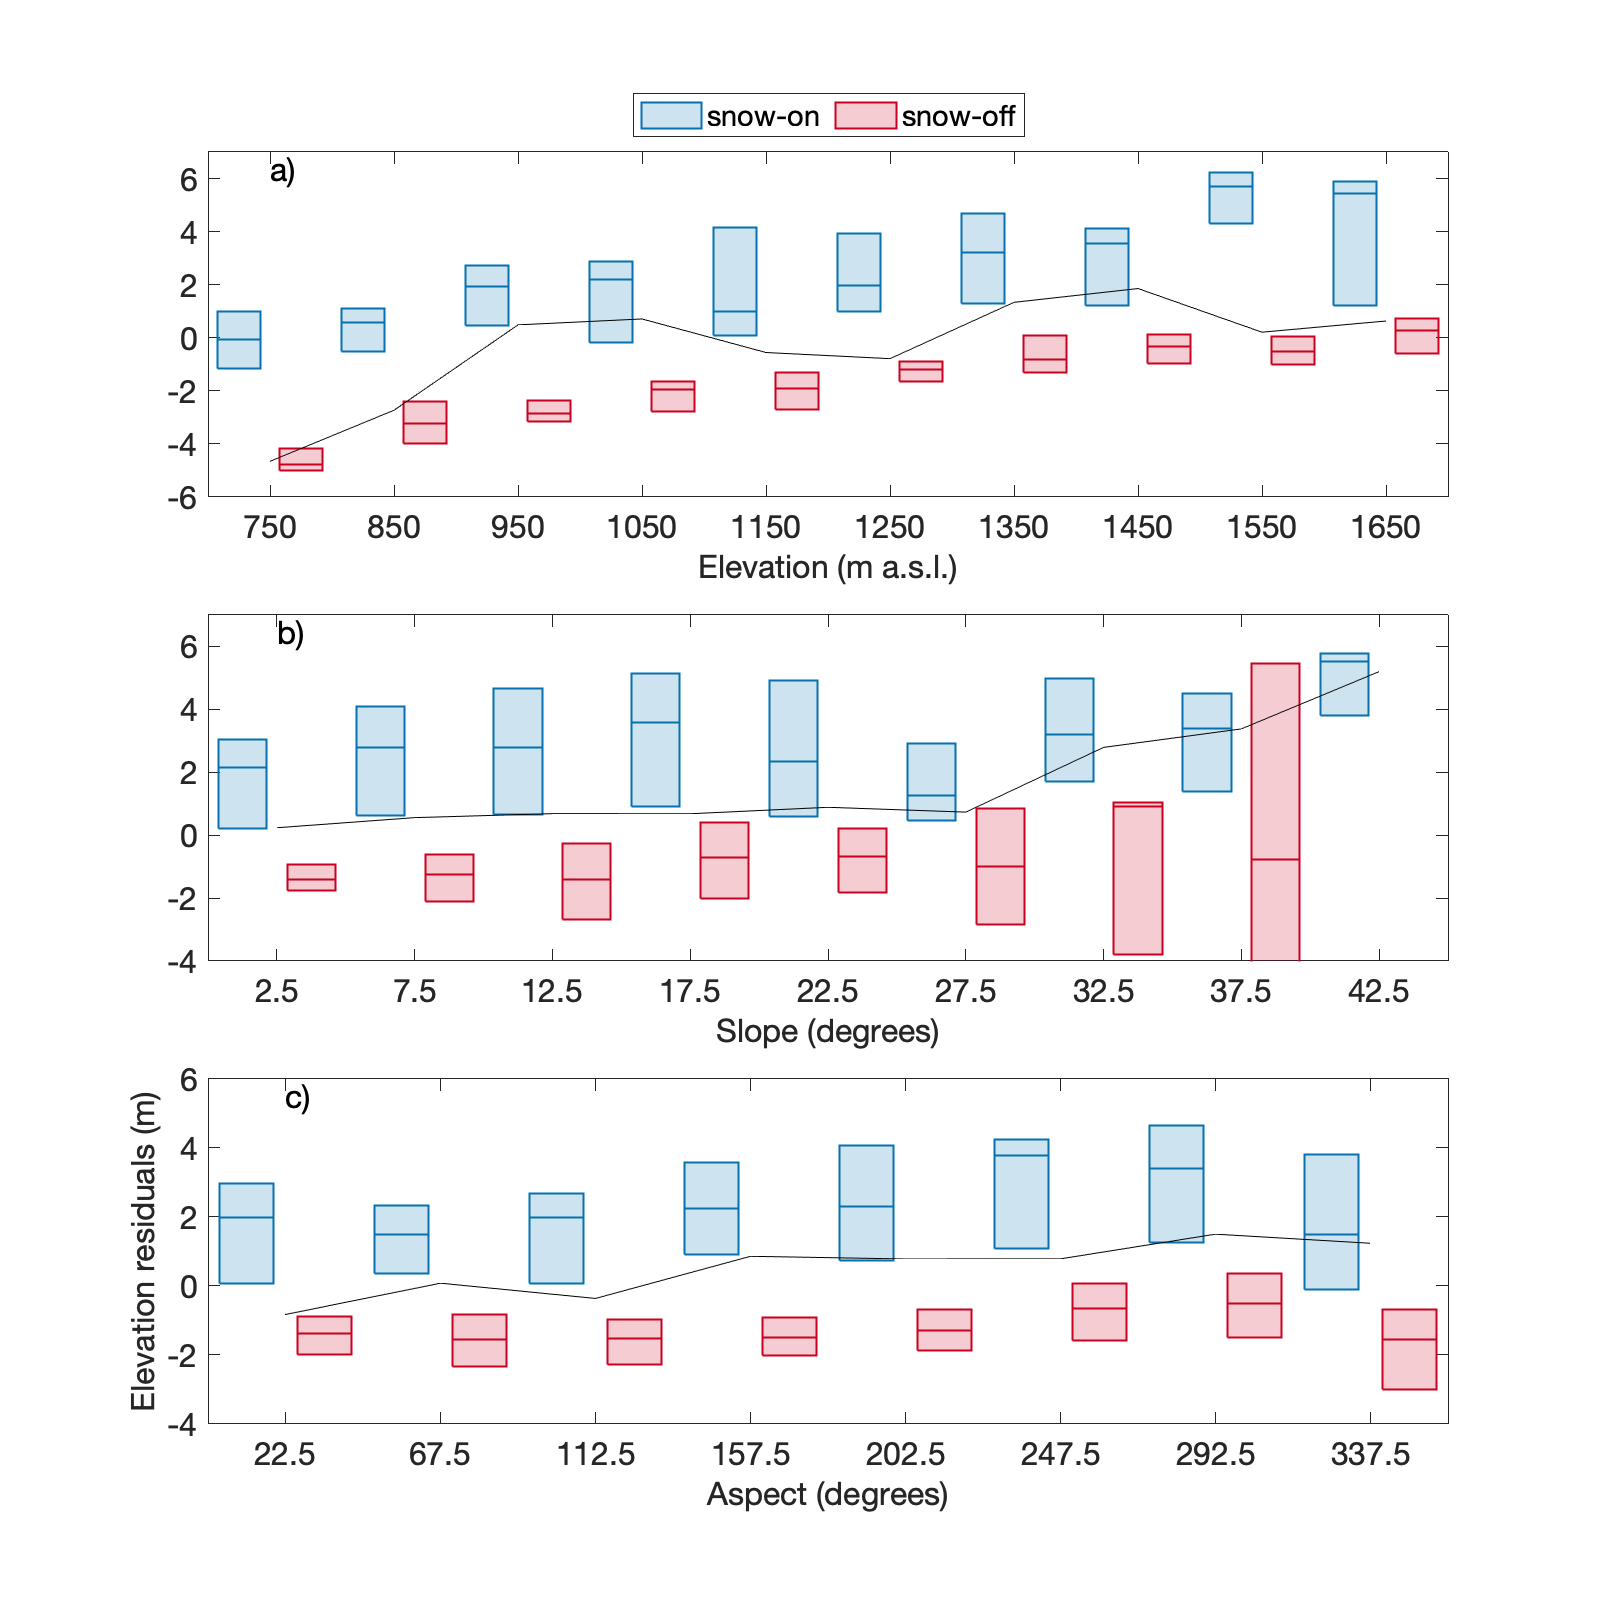

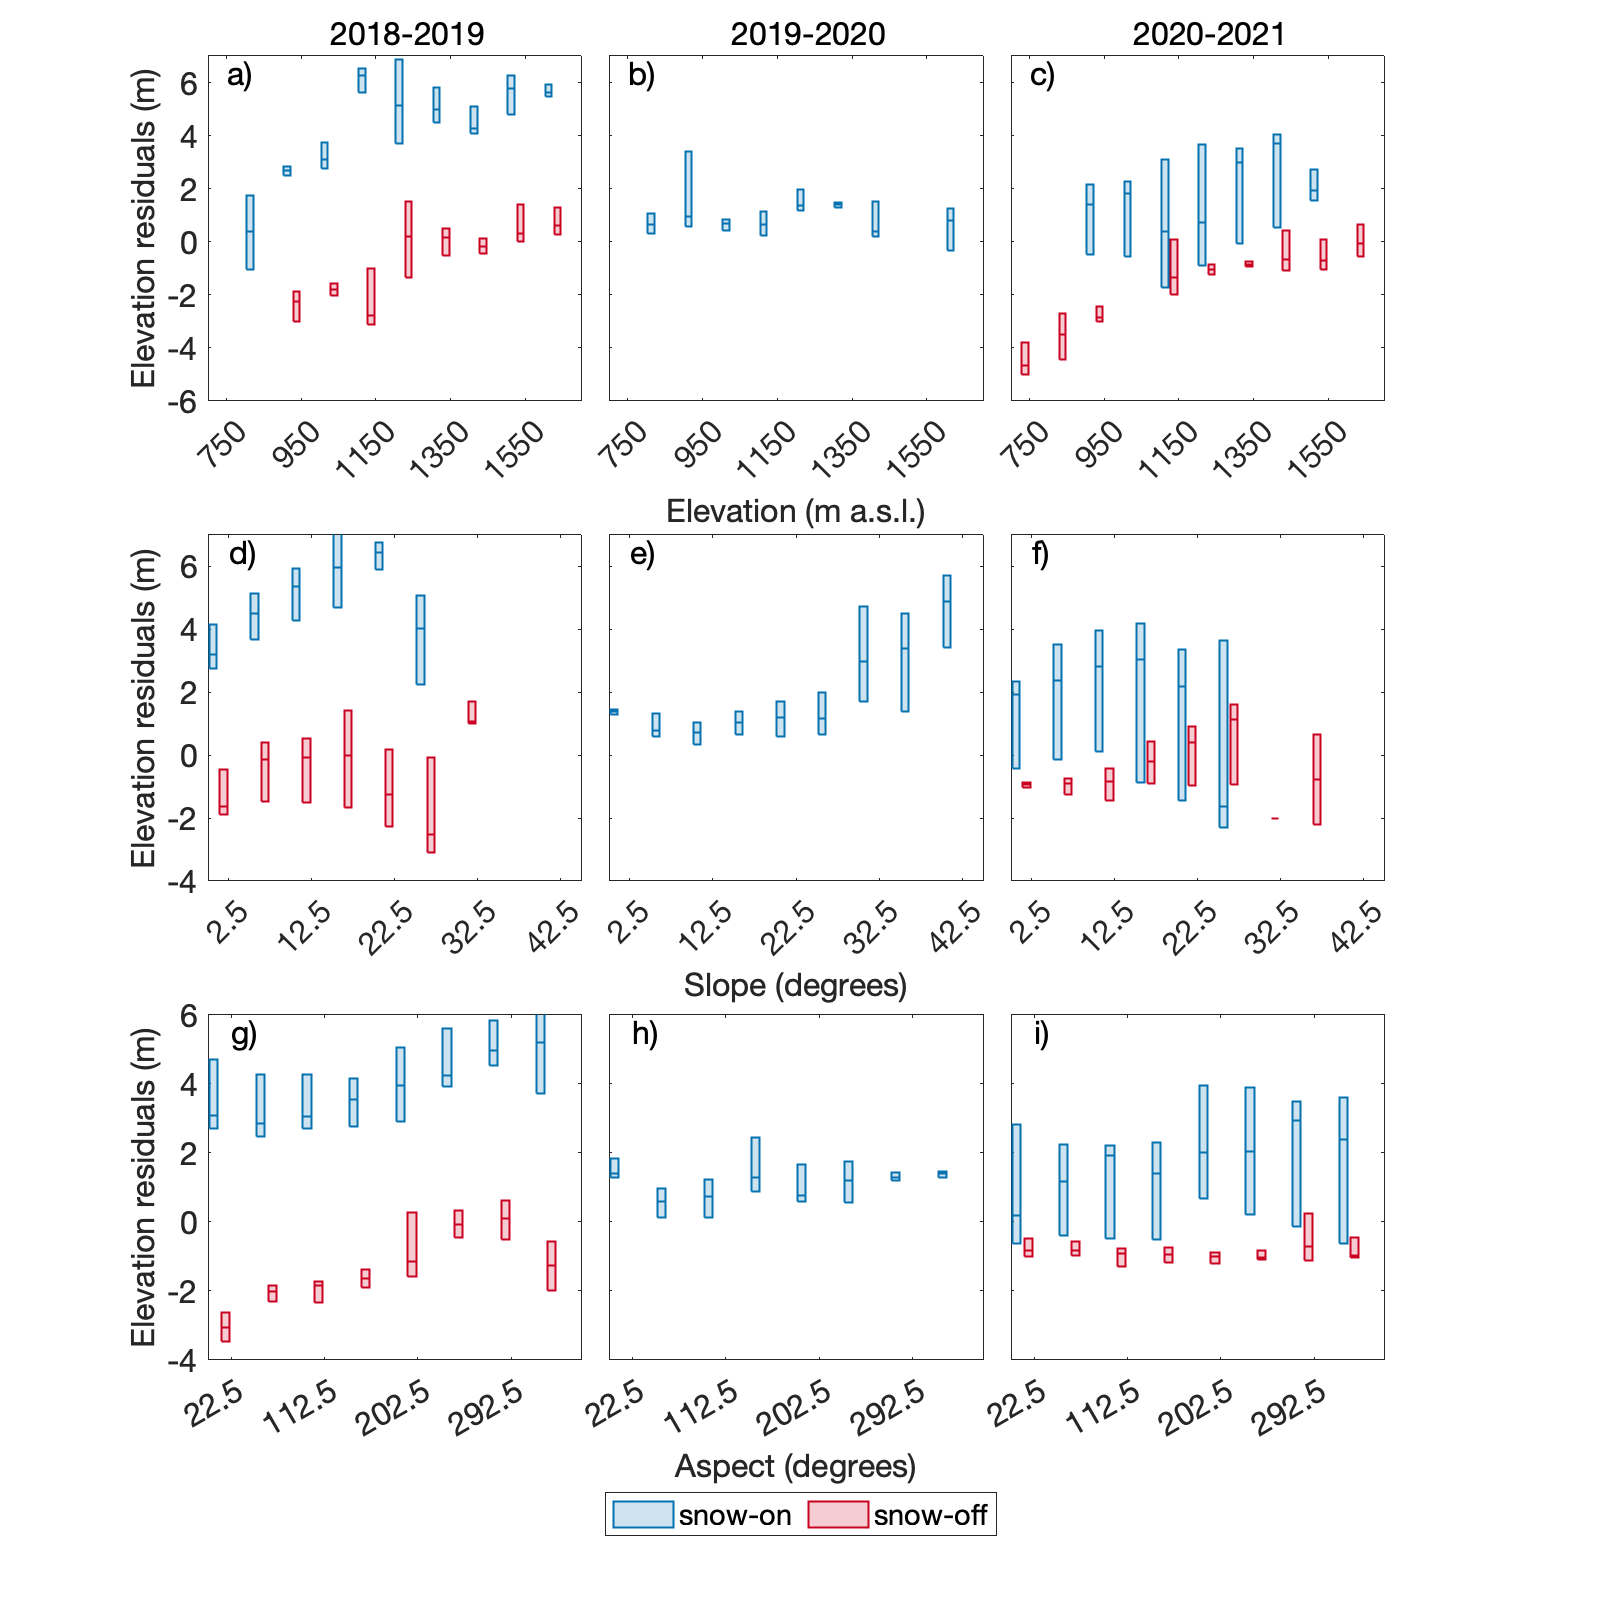

cd(csv_path);

%uncomment while loops to automatically determine bin widths for each parameter by identifying the
%bin width that yields >100 observations for the complete dataset
%ELEVATION
h = histogram(Tin.ReferenceElevation(~isnan(Tin.differences)),[floor(min(elev_x)/100)*100:100:ceil(max(elev_x)/100)*100]);
% p = 1;
% while p
%     if median(h.Values) < 100
%     fewerbins(h);
%     else
elev_binwidth = h.BinWidth; elev_binedges = h.BinEdges;
clear h;
%         break
%     end
% end
close(gcf);
%SLOPE
h = histogram(Tin.slope(~isnan(Tin.differences)),[0:5:max(slope_x)]);
% p = 1;
% while p
%     if median(h.Values) < 100
%     fewerbins(h);
%     else
slope_binwidth = h.BinWidth; slope_binedges = h.BinEdges;
clear h;
%         break
%     end
% end
close(gcf);
%ASPECT
h = histogram(Tin.aspect(~isnan(Tin.differences)),[0:45:360]);
% p = 1;
% while p
%     if median(h.Values) < 100
%     fewerbins(h);
%     else
aspect_binwidth = h.BinWidth; aspect_binedges = h.BinEdges;
clear h;
%         break
%     end
% end
close(gcf);

%create boxplot colormaps
% boxplot_cmap = [wincolor; sprcolor; sumcolor; falcolor];
boxplot_cmap = seas_cmap;

%create boxcharts w/ and w/o whiskers+outliers
for p = 1:2
    
    %specify plot parameters
    if p == 1
        whiskerline = '-'; outliermarker = 'o';
        resid_ylims = [-10 10]; resid_elev_ylims = resid_ylims; resid_elev_ytick = [-10:5:10];
        resid_slope_ylims = resid_ylims; resid_aspect_ylims = resid_ylims;
    else
        whiskerline = 'none'; outliermarker = 'none';
        resid_ylims = [-3.5 2.5]; resid_elev_ylims = [-6 7]; resid_elev_ytick = [-6:2:7];
        resid_slope_ylims = [-4 7.0]; resid_aspect_ylims = [-4 6.0];
    end
    
    %create boxcharts for each terrain parameter
    figure('position', [0 0 800 800]);
    plot_boxwidth = 0.7; 
    %ELEVATION
    subplot(3,1,1);
    elev_binflag = zeros(size(Tin.differences,1),1);
    for j = 1:length(elev_binedges)-1
        binref = find(Tin.ReferenceElevation>=elev_binedges(j) & Tin.ReferenceElevation<elev_binedges(j+1));
        elev_binflag(binref,1) = nanmean(elev_binedges(j:j+1)); clear binref;
    end
    resids_elev = Tin.differences(elev_binflag>0); elev_seasflag = Tin.season(elev_binflag>0); elev_binflag(elev_binflag==0) = [];
    elev_seasflag(isnan(resids_elev)) = []; elev_binflag(isnan(resids_elev)) = []; resids_elev(isnan(resids_elev)) = []; 
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    elev_seasflag(elev_seasflag ~= 3) = 1; elev_seasflag(elev_seasflag == 3) = 2;
    %filter crazy outliers
    resids_elev(resids_elev > nanmedian(Tin.differences)+10*mad(Tin.differences,1)) = NaN;
    resids_elev(resids_elev < nanmedian(Tin.differences)-10*mad(Tin.differences,1)) = NaN;
    b = boxchart(categorical(elev_binflag),resids_elev(:,1),'GroupByColor',elev_seasflag,...
        'BoxWidth',plot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker); hold on;
    medianresid = groupsummary(resids_elev(:,1),categorical(elev_binflag),'median');
    plot(medianresid,'-','color','k'); hold off; elevbin = unique(elev_binflag);
    clear medianresid;
    for j = 1:size(boxplot_cmap,1)
        b(j).BoxFaceColor = boxplot_cmap(j,:); b(j).MarkerColor = boxplot_cmap(j,:);
    end
    set(gca,'ylim',resid_elev_ylims,'ytick',resid_elev_ytick);
    set(gca,'fontsize',16,'box','on'); drawnow;
    if p == 2
        pos = get(gca,'position');
        %     leg = legend('winter','spring','summer','autumn','location','northoutside','Orientation','horizontal');
        leg = legend('snow-on','snow-off','location','northoutside','orientation','horizontal');
        set(gca,'position',[pos(1) pos(2)-0.02 pos(3) pos(4)]);
    end
    xlabel('Elevation (m a.s.l.)','fontsize',16); %ylabel('Elevation residuals (m)','fontsize',16);
    ylims = get(gca,'ylim');
    text(1,max(ylims)-0.05*range(ylims),'a)','fontsize',16);
    %SLOPE
    subplot(3,1,2);
    slope_binflag = zeros(size(Tin.differences,1),1);
    for j = 1:length(slope_binedges)-1
        binref = find(Tin.slope>=slope_binedges(j) & Tin.slope<slope_binedges(j+1));
        slope_binflag(binref,1) = nanmean(slope_binedges(j:j+1)); clear binref;
    end
    resids_slope = Tin.differences(slope_binflag>0); slope_seasflag = Tin.season(slope_binflag>0); slope_binflag(slope_binflag==0) = [];
    slope_seasflag(isnan(resids_slope)) = []; slope_binflag(isnan(resids_slope)) = []; resids_slope(isnan(resids_slope)) = []; 
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    slope_seasflag(slope_seasflag ~= 3) = 1; slope_seasflag(slope_seasflag == 3) = 2;
    %filter crazy outliers
    resids_slope(resids_slope > nanmedian(Tin.differences)+10*mad(Tin.differences,1)) = NaN;
    resids_slope(resids_slope < nanmedian(Tin.differences)-10*mad(Tin.differences,1)) = NaN;
    b = boxchart(categorical(slope_binflag),resids_slope(:,1),'GroupByColor',slope_seasflag,...
        'BoxWidth',plot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker); hold on;
    medianresid = groupsummary(resids_slope(:,1),categorical(slope_binflag),'median');
    plot(medianresid,'-','color','k'); hold off; slopebin = unique(slope_binflag);
    clear medianresid;
    for j = 1:size(boxplot_cmap,1)
        b(j).BoxFaceColor = boxplot_cmap(j,:); b(j).MarkerColor = boxplot_cmap(j,:);
    end
    set(gca,'ylim',resid_slope_ylims);
    set(gca,'fontsize',16,'box','on'); drawnow;
    if p == 2
        pos = get(gca,'position');
        set(gca,'position',[pos(1) pos(2)-0.01 pos(3) pos(4)]);
    end
    xlabel('Slope (degrees)','fontsize',16); %ylabel('Elevation residuals (m)','fontsize',16);
    ylims = get(gca,'ylim');
    text(1,max(ylims)-0.05*range(ylims),'b)','fontsize',16);
    %ASPECT
    subplot(3,1,3);
    aspect_binflag = zeros(size(Tin.differences,1),1);
    for j = 1:length(aspect_binedges)-1
        binref = find(Tin.aspect>=aspect_binedges(j) & Tin.aspect<aspect_binedges(j+1));
        aspect_binflag(binref,1) = nanmean(aspect_binedges(j:j+1)); clear binref;
    end
    resids_aspect = Tin.differences(aspect_binflag>0); aspect_seasflag = Tin.season(aspect_binflag>0); aspect_binflag(aspect_binflag==0) = [];
    aspect_seasflag(isnan(resids_aspect)) = []; aspect_binflag(isnan(resids_aspect)) = []; resids_aspect(isnan(resids_aspect)) = []; 
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    aspect_seasflag(aspect_seasflag ~= 3) = 1; aspect_seasflag(aspect_seasflag == 3) = 2;
    %filter crazy outliers
    resids_aspect(resids_aspect > nanmedian(Tin.differences)+10*mad(Tin.differences,1)) = NaN;
    resids_aspect(resids_aspect < nanmedian(Tin.differences)-10*mad(Tin.differences,1)) = NaN;
    b = boxchart(categorical(aspect_binflag),resids_aspect(:,1),'GroupByColor',aspect_seasflag,...
        'BoxWidth',plot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker); hold on;
    medianresid = groupsummary(resids_aspect(:,1),categorical(aspect_binflag),'median');
    plot(medianresid,'-','color','k'); hold off;
    clear medianresid;
    for j = 1:size(boxplot_cmap,1)
        b(j).BoxFaceColor = boxplot_cmap(j,:); b(j).MarkerColor = boxplot_cmap(j,:);
    end
    set(gca,'ylim',resid_aspect_ylims);
    set(gca,'fontsize',16,'box','on'); drawnow;
    % leg = legend('winter','spring','summer','autumn','location','southeast');
    xlabel('Aspect (degrees)','fontsize',16); ylabel('Elevation residuals (m)','fontsize',16);
    ylims = get(gca,'ylim');
    text(1,max(ylims)-0.05*range(ylims),'c)','fontsize',16);
    %save figure
    if p == 1
        saveas(gcf,[figure_path,abbrev,'_ICESat2residuals-vs-terrain_boxplots.eps'],'epsc');
    else
        saveas(gcf,[figure_path,abbrev,'_ICESat2residuals-vs-terrain_whiskerless-boxplots.eps'],'epsc');
    end
    clear resids_* *binflag* *seasflag*
    
    
    %divide according to year as well (subplot rows = parameters, columns = years of data)
    figure('Position',[0 0 800 800]);
    subplot_boxwidth = 0.7; subplot_markersize = 2;
    %ELEVATION
    elev_binflag = zeros(size(Tin.differences,1),1);
    for j = 1:length(elev_binedges)-1
        binref = find(Tin.ReferenceElevation>=elev_binedges(j) & Tin.ReferenceElevation<elev_binedges(j+1));
        elev_binflag(binref,1) = nanmean(elev_binedges(j:j+1)); clear binref;
    end
    resids_elev = Tin.differences(elev_binflag~=0); elev_seasflag = Tin.season(elev_binflag~=0); elev_binflag(elev_binflag==0) = [];
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    elev_seasflag(elev_seasflag ~= 3) = 1; elev_seasflag(elev_seasflag == 3) = 2;
    %filter crazy outliers
    resids_elev(resids_elev > nanmedian(Tin.differences)+10*mad(Tin.differences,1)) = NaN;
    resids_elev(resids_elev < nanmedian(Tin.differences)-10*mad(Tin.differences,1)) = NaN;
    for j = 1:length(Z)
        dyear = Tin.date(elev_binflag~=0) - Z(j).deciyear;
        resids_elev_annual = resids_elev(ceil(dyear)==1); elev_seasflag_annual = elev_seasflag(ceil(dyear)==1); elev_binflag_annual = elev_binflag(ceil(dyear)==1);
        resids_elev_annual = resids_elev_annual(elev_binflag_annual>0); elev_seasflag_annual = elev_seasflag_annual(elev_binflag_annual>0); elev_binflag_annual(elev_binflag_annual==0) = [];
        elev_seasflag_annual(isnan(resids_elev_annual)) = []; elev_binflag_annual(isnan(resids_elev_annual)) = []; resids_elev_annual(isnan(resids_elev_annual)) = [];
        subplot(3,length(Z),j);
        b = boxchart(categorical([elev_binflag_annual(elev_binflag_annual>0); repmat(unique(elev_binflag(elev_binflag>0)),4,1)]),[resids_elev_annual(elev_binflag_annual>0); NaN(4*length(unique(elev_binflag(elev_binflag>0))),1)],...
            'GroupByColor',[elev_seasflag_annual(elev_binflag_annual>0);ones(length(unique(elev_binflag(elev_binflag>0))),1);2*ones(length(unique(elev_binflag(elev_binflag>0))),1);3*ones(length(unique(elev_binflag(elev_binflag>0))),1);4*ones(length(unique(elev_binflag(elev_binflag>0))),1)],...
            'BoxWidth',subplot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker);
        for k = 1:size(boxplot_cmap,1)
            b(k).BoxFaceColor = boxplot_cmap(k,:); b(k).MarkerColor = boxplot_cmap(k,:); b(k).MarkerSize = subplot_markersize;
        end
        set(gca,'ylim',resid_elev_ylims,'ytick',resid_elev_ytick); pos = get(gca,'position');
        set(gca,'fontsize',16,'box','on'); drawnow;
        xticks = get(gca,'xtick'); set(gca,'xtick',xticks(1:2:end));
        if j == 1
            ylabel('Elevation residuals (m)','fontsize',16);
            set(gca,'position',[pos(1) pos(2)+0.04 pos(3)+0.02 pos(4)]);
        elseif j == 2
            xlabel('Elevation (m a.s.l.)','fontsize',16);
            set(gca,'yticklabel',[],'position',[pos(1)-0.03 pos(2)+0.04 pos(3)+0.02 pos(4)]);
        elseif j==3
            set(gca,'yticklabel',[]);
            %         leg = legend('winter','spring','summer','autumn','location','eastoutside');
            set(gca,'position',[pos(1)-0.06 pos(2)+0.04 pos(3)+0.02 pos(4)])
        end
        pos = get(gca,'position'); ylims = get(gca,'ylim');
        annotation('textbox',[pos(1)+0.3*pos(3) pos(2)+pos(4)+0.01 0.1 0.02],'string',[num2str(floor(Z(j).deciyear)),'-',num2str(ceil(Z(j).deciyear))],'fontsize',16,'edgecolor','none');
        text(1,max(ylims)-0.05*range(ylims),[alphabet(j),')'],'fontsize',16);
        
         %report statistics for each season
         if p == 1
             %snow-on and snow-off times of the year
             snowresids = resids_elev_annual(elev_seasflag_annual==1); snowelevs = elev_binflag_annual(elev_seasflag_annual==1);
             dryresids = resids_elev_annual(elev_seasflag_annual==2); dryelevs = elev_binflag_annual(elev_seasflag_annual==2);
             elev_bins = unique(elev_binflag_annual);
             for k = 1:length(elev_bins)
                 snowmed(k) = nanmedian(snowresids(snowelevs==elev_bins(k)));
                 drymed(k) = nanmedian(dryresids(dryelevs==elev_bins(k)));
             end
             %fit linear polynomials & display data summary
             if nansum(snowelevs) > 2
                 [snowfit,~] = fit(snowelevs,snowresids,'poly1');
                 disp([num2str(Z(j).deciyear),' snow-on :']);
                 disp(['min = ',num2str(min(snowmed)),'m, max = ',num2str(max(snowmed)),'m, gradient = ',num2str(snowfit.p1),'m/m']);
             end
             if nansum(dryelevs) > 2
                 [dryfit,~] = fit(dryelevs,dryresids,'poly1');
                 disp([num2str(Z(j).deciyear),' snow-off :']);
                 disp(['min = ',num2str(min(drymed)),'m, max = ',num2str(max(drymed)),'m, gradient = ',num2str(dryfit.p1),'m/m']);
             end
         end
        clear dyear b medianresid *resids *elevs elev_bins *fit *med;
    end
    %SLOPE
    slope_binflag = zeros(size(Tin.slope,1),1);
    for j = 1:length(slope_binedges)-1
        binref = find(Tin.slope>=slope_binedges(j) & Tin.slope<slope_binedges(j+1));
        slope_binflag(binref,1) = nanmean(slope_binedges(j:j+1)); clear binref;
    end
    resids_slope = Tin.differences; slope_seasflag = Tin.season;
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    slope_seasflag(slope_seasflag ~= 3) = 1; slope_seasflag(slope_seasflag == 3) = 2;
    %filter crazy outliers
    resids_slope(resids_slope > nanmedian(Tin.differences)+10*mad(Tin.differences,1)) = NaN;
    resids_slope(resids_slope < nanmedian(Tin.differences)-10*mad(Tin.differences,1)) = NaN;
    for j = 1:length(Z)
        dyear = Tin.date - Z(j).deciyear;
        resids_slope_annual = resids_slope(ceil(dyear)==1); slope_seasflag_annual = slope_seasflag(ceil(dyear)==1); slope_binflag_annual = slope_binflag(ceil(dyear)==1);
        subplot(3,length(Z),length(Z)+j);
        b = boxchart(categorical([slope_binflag_annual(slope_binflag_annual>0); repmat(unique(slope_binflag(slope_binflag>0)),4,1)]),[resids_slope_annual(slope_binflag_annual>0); NaN(4*length(unique(slope_binflag(slope_binflag>0))),1)],...
            'GroupByColor',[slope_seasflag_annual(slope_binflag_annual>0);ones(length(unique(slope_binflag(slope_binflag>0))),1);2*ones(length(unique(slope_binflag(slope_binflag>0))),1);3*ones(length(unique(slope_binflag(slope_binflag>0))),1);4*ones(length(unique(slope_binflag(slope_binflag>0))),1)],...
            'BoxWidth',subplot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker);
        for k = 1:size(boxplot_cmap,1)
            b(k).BoxFaceColor = boxplot_cmap(k,:); b(k).MarkerColor = boxplot_cmap(k,:); b(k).MarkerSize = subplot_markersize;
        end
        set(gca,'ylim',resid_slope_ylims); pos = get(gca,'position');
        set(gca,'fontsize',16,'box','on'); drawnow;
        xticks = get(gca,'xtick'); set(gca,'xtick',xticks(1:2:end));
        if j == 1
            ylabel('Elevation residuals (m)','fontsize',16);
            set(gca,'position',[pos(1) pos(2)+0.04 pos(3)+0.02 pos(4)]);
        elseif j == 2
            xlabel('Slope (degrees)','fontsize',16);
            set(gca,'yticklabel',[],'position',[pos(1)-0.03 pos(2)+0.04 pos(3)+0.02 pos(4)]);
        elseif j==3
            set(gca,'yticklabel',[]);
%             leg = legend('winter','spring','summer','autumn','location','southoutside','Orientation','horizontal');
            leg = legend('snow-on','snow-off','location','southoutside','orientation','horizontal');
            set(gca,'position',[pos(1)-0.06 pos(2)+0.04 pos(3)+0.02 pos(4)])
        end
        ylims = get(gca,'ylim');
        text(1,max(ylims)-0.05*range(ylims),[alphabet(length(Z)+j),')'],'fontsize',16);
        clear dyear b;
    end
    %ASPECT
    aspect_binflag = zeros(size(Tin.aspect,1),1);
    for j = 1:length(aspect_binedges)-1
        binref = find(Tin.aspect>=aspect_binedges(j) & Tin.aspect<aspect_binedges(j+1));
        aspect_binflag(binref,1) = nanmean(aspect_binedges(j:j+1)); clear binref;
    end
    resids_aspect = Tin.differences; aspect_seasflag = Tin.season;
    %modify seasonal flag to simplify to just snow-on (1&4=1) and snow-off(2&3=2) seasons
    aspect_seasflag(aspect_seasflag ~= 3) = 1; aspect_seasflag(aspect_seasflag == 3) = 2;
    %filter crazy outliers
    resids_aspect(resids_aspect > nanmedian(Tin.differences)+10*mad(Tin.differences,1)) = NaN;
    resids_aspect(resids_aspect < nanmedian(Tin.differences)-10*mad(Tin.differences,1)) = NaN;
    for j = 1:length(Z)
        dyear = Tin.date - Z(j).deciyear;
        resids_aspect_annual = resids_aspect(ceil(dyear)==1); aspect_seasflag_annual = aspect_seasflag(ceil(dyear)==1); aspect_binflag_annual = aspect_binflag(ceil(dyear)==1);
        subplot(3,length(Z),2*length(Z)+j);
        b = boxchart(categorical([aspect_binflag_annual(aspect_binflag_annual>0); repmat(unique(aspect_binflag(aspect_binflag>0)),4,1)]),[resids_aspect_annual(aspect_binflag_annual>0); NaN(4*length(unique(aspect_binflag(aspect_binflag>0))),1)],...
            'GroupByColor',[aspect_seasflag_annual(aspect_binflag_annual>0);ones(length(unique(aspect_binflag(aspect_binflag>0))),1);2*ones(length(unique(aspect_binflag(aspect_binflag>0))),1);3*ones(length(unique(aspect_binflag(aspect_binflag>0))),1);4*ones(length(unique(aspect_binflag(aspect_binflag>0))),1)],...
            'BoxWidth',subplot_boxwidth,'WhiskerLineStyle',whiskerline,'MarkerStyle',outliermarker);
        for k = 1:size(boxplot_cmap,1)
            b(k).BoxFaceColor = boxplot_cmap(k,:); b(k).MarkerColor = boxplot_cmap(k,:); b(k).MarkerSize = subplot_markersize;
        end
        set(gca,'ylim',resid_aspect_ylims); pos = get(gca,'position');
        set(gca,'fontsize',16,'box','on'); drawnow;
        xticks = get(gca,'xtick'); set(gca,'xtick',xticks(1:2:end));
        if j == 1
            ylabel('Elevation residuals (m)','fontsize',16);
            set(gca,'position',[pos(1) pos(2)+0.04 pos(3)+0.02 pos(4)]);
        elseif j == 2
            xlabel('Aspect (degrees)','fontsize',16);
            set(gca,'yticklabel',[],'position',[pos(1)-0.03 pos(2)+0.04 pos(3)+0.02 pos(4)]);
        elseif j==3
            set(gca,'yticklabel',[]);
            %         leg = legend('winter','spring','summer','autumn','location','eastoutside');
            set(gca,'position',[pos(1)-0.06 pos(2)+0.04 pos(3)+0.02 pos(4)])
        end
        ylims = get(gca,'ylim');
        text(1,max(ylims)-0.05*range(ylims),[alphabet(2*length(Z)+j),')'],'fontsize',16);
        clear dyear b;
    end
    legpos = get(leg,'position'); set(leg,'position',[0.5-(0.5*legpos(3)) 0.04 legpos(3) legpos(4)]);
    %save figure
    if p == 1
        saveas(gcf,[figure_path,abbrev,'_ICESat2residuals-vs-terrain_annual-boxplots.eps'],'epsc');
    else
        saveas(gcf,[figure_path,abbrev,'_ICESat2residuals-vs-terrain_whiskerless-annual-boxplots.eps'],'epsc');
    end
    
end

## Fit curves to snow-off elevation residuals vs terrain parameters

fprintf('Characterizing snow-off bias & uncertainty...')

Characterizing snow-off bias & uncertainty...


%isolate the snow-off data
soffdiff = Tin.differences(Tin.season==3);
soffelev = Tin.Elevation(Tin.season==3);
soffslope = Tin.slope(Tin.season==3);
soffaspect = Tin.aspect(Tin.season==3);

%calculate the median elevation residual for each terrain parameter bin from last section
%ELEVATION
for j = 1:length(elev_binedges)-1
    soffdiff_elev(j) = nanmedian(soffdiff(soffelev>=elev_binedges(j) & soffelev<elev_binedges(j+1)));
    soffdiff_elevIQR(j) = iqr(soffdiff(soffelev>=elev_binedges(j) & soffelev<elev_binedges(j+1)));
    soffdiff_elevMAD(j) = mad(soffdiff(soffelev>=elev_binedges(j) & soffelev<elev_binedges(j+1)),1);
    soffdiff_elevno(j) = length(soffdiff(soffelev>=elev_binedges(j) & soffelev<elev_binedges(j+1)));
    soffdiff_elevbin(j) = nanmean([elev_binedges(j:j+1)]);
end
soffdiff_elev(soffdiff_elevno<100) = []; soffdiff_elevbin(soffdiff_elevno<100) = []; 
soffdiff_elevIQR(soffdiff_elevno<100) = []; soffdiff_elevMAD(soffdiff_elevno<100) = []; soffdiff_elevno(soffdiff_elevno<100) = [];
%SLOPE
for j = 1:length(slope_binedges)-1
    soffdiff_slope(j) = nanmedian(soffdiff(soffslope>=slope_binedges(j) & soffslope<slope_binedges(j+1)));
    soffdiff_slopeIQR(j) = iqr(soffdiff(soffslope>=slope_binedges(j) & soffslope<slope_binedges(j+1)));
    soffdiff_slopeMAD(j) = mad(soffdiff(soffslope>=slope_binedges(j) & soffslope<slope_binedges(j+1)),1);
    soffdiff_slopeno(j) = length(soffdiff(soffslope>=slope_binedges(j) & soffslope<slope_binedges(j+1)));
    soffdiff_slopebin(j) = nanmean([slope_binedges(j:j+1)]);
end
soffdiff_slope(soffdiff_slopeno<100) = []; soffdiff_slopebin(soffdiff_slopeno<100) = []; 
soffdiff_slopeIQR(soffdiff_slopeno<100) = []; soffdiff_slopeMAD(soffdiff_slopeno<100) = []; soffdiff_slopeno(soffdiff_slopeno<100) = [];
%ASPECT
for j = 1:length(aspect_binedges)-1
    soffdiff_aspect(j) = nanmedian(soffdiff(soffaspect>=aspect_binedges(j) & soffaspect<aspect_binedges(j+1)));
    soffdiff_aspectIQR(j) = iqr(soffdiff(soffaspect>=aspect_binedges(j) & soffaspect<aspect_binedges(j+1)));
    soffdiff_aspectMAD(j) = mad(soffdiff(soffaspect>=aspect_binedges(j) & soffaspect<aspect_binedges(j+1)),1);
    soffdiff_aspectno(j) = length(soffdiff(soffaspect>=aspect_binedges(j) & soffaspect<aspect_binedges(j+1)));
    soffdiff_aspectbin(j) = nanmean([aspect_binedges(j:j+1)]);
end
soffdiff_aspect(soffdiff_aspectno<100) = []; soffdiff_aspectbin(soffdiff_aspectno<100) = []; 
soffdiff_aspectIQR(soffdiff_aspectno<100) = []; soffdiff_aspectMAD(soffdiff_aspectno<100) = []; soffdiff_aspectno(soffdiff_aspectno<100) = [];

%fit curves
%ELEVATION
fprintf('Elevation residuals vs elevation:')

Elevation residuals vs elevation:

[f1,gof1] = fit(soffdiff_elevbin(~isnan(soffdiff_elev))',soffdiff_elev(~isnan(soffdiff_elev))','poly1'); 
[f2,gof2] = fit(soffdiff_elevbin(~isnan(soffdiff_elev))',soffdiff_elev(~isnan(soffdiff_elev))','poly2');
%print info on variations in the bias & uncertainty with the terrain parameter
fprintf('Linear fit = %3.2s x + %3.2s w/ R^2 = %4.3f',f1.p1,f1.p2,gof1.rsquare);

Linear fit = 4.65e-03 x + -7.07e+00 w/ R^2 = 0.971

fprintf('Quadratic fit = %3.2s x^2 + %3.2s x + %3.2s w/ R^2 = %4.3f',f2.p1,f2.p2,f2.p3,gof2.rsquare);

Quadratic fit = 4.66e-07 x^2 + 3.53e-03 x + -6.41e+00 w/ R^2 = 0.971

fprintf('Bias for min & max elevation bins = [%3.2f,%3.2f]',soffdiff_elev(1),soffdiff_elev(end));

Bias for min & max elevation bins = [-2.72,-0.30]

fprintf('IQR for min & max elevation bins = [%3.2f,%3.2f]',soffdiff_elevIQR(1),soffdiff_elevIQR(end));

IQR for min & max elevation bins = [0.99,1.13]

fprintf('MAD for min & max elevation bins = [%3.2f,%3.2f]',soffdiff_elevMAD(1),soffdiff_elevMAD(end));

MAD for min & max elevation bins = [0.46,0.57]

clear *f1 *f2;
%SLOPE
fprintf('Elevation residuals vs slope:')

Elevation residuals vs slope:

[f1,gof1] = fit(soffdiff_slopebin(~isnan(soffdiff_slope))',soffdiff_slope(~isnan(soffdiff_slope))','poly1'); 
[f2,gof2] = fit(soffdiff_slopebin(~isnan(soffdiff_slope))',soffdiff_slope(~isnan(soffdiff_slope))','poly2');
%print info on variations in the bias & uncertainty with the terrain parameter
if gof1.rsquare > gof2.rsquare
    fprintf('Linear fit = %3.2s x + %3.2s w/ R^2 = %4.3f',f1.p1,f1.p2,gof1.rsquare);
else
    fprintf('Quadratic fit = %3.2s x^2 + %3.2s x + %3.2s w/ R^2 = %4.3f',f2.p1,f2.p2,f2.p3,gof2.rsquare);
end

Quadratic fit = 5.04e-03 x^2 + -6.12e-02 x + -1.22e+00 w/ R^2 = 0.859

fprintf('Bias for min & max slope bins = [%3.2f,%3.2f]',soffdiff_slope(1),soffdiff_slope(end));

Bias for min & max slope bins = [-1.39,-0.70]

fprintf('IQR for min & max slope bins = [%3.2f,%3.2f]',soffdiff_slopeIQR(1),soffdiff_slopeIQR(end));

IQR for min & max slope bins = [0.86,2.41]

fprintf('MAD for min & max slope bins = [%3.2f,%3.2f]',soffdiff_slopeMAD(1),soffdiff_slopeMAD(end));

MAD for min & max slope bins = [0.42,1.17]

clear *f1 *f2;
%ASPECT
fprintf('Elevation residuals vs aspect:')

Elevation residuals vs aspect:

[f1,gof1] = fit(soffdiff_aspectbin(~isnan(soffdiff_aspect))',soffdiff_aspect(~isnan(soffdiff_aspect))',ft2);

%print info on variations in the bias & uncertainty with the terrain parameter
fprintf('Custom sinusoffidal fit = %3.2s * cosd(x + %3.2s) + %3.2f w/ R^2 = %4.3f',f1.a,f1.b,f1.c,gof1.rsquare);

Custom sinusoffidal fit = 4.83e-01 * cosd(x + 9.06e+01) + -1.23 w/ R^2 = 0.677

fprintf('Bias for SE & NW aspect bins = [%3.2f,%3.2f]',soffdiff_aspect(2),soffdiff_aspect(6));

Bias for SE & NW aspect bins = [-1.60,-0.63]

fprintf('IQR for SE & NW  aspect bins = [%3.2f,%3.2f]',soffdiff_aspectIQR(2),soffdiff_aspectIQR(6));

IQR for SE & NW  aspect bins = [1.52,1.68]

fprintf('MAD for SE & NW  aspect bins = [%3.2f,%3.2f]',soffdiff_aspectMAD(2),soffdiff_aspectMAD(6));

MAD for SE & NW  aspect bins = [0.76,0.82]

clear *f1;

%repeat characterization of elevation residuals with respect to terrain
%parameters for the snow on dataset
fprintf('Characterizing snow-on terrain dependency...')

Characterizing snow-on terrain dependency...

sondiff = Tin.differences(Tin.season~=3 & (Tin.date < Z(2).deciyear | Tin.date >= Z(3).deciyear));
sonelev = Tin.Elevation(Tin.season~=3 & (Tin.date < Z(2).deciyear | Tin.date >= Z(3).deciyear));
sonslope = Tin.slope(Tin.season~=3 & (Tin.date < Z(2).deciyear | Tin.date >= Z(3).deciyear));
sonaspect = Tin.aspect(Tin.season~=3 & (Tin.date < Z(2).deciyear | Tin.date >= Z(3).deciyear));

%calculate the median elevation residual for each terrain parameter bin from last section
%ELEVATION
for j = 1:length(elev_binedges)-1
    sondiff_elev(j) = nanmedian(sondiff(sonelev>=elev_binedges(j) & sonelev<elev_binedges(j+1)));
    sondiff_elevIQR(j) = iqr(sondiff(sonelev>=elev_binedges(j) & sonelev<elev_binedges(j+1)));
    sondiff_elevMAD(j) = mad(sondiff(sonelev>=elev_binedges(j) & sonelev<elev_binedges(j+1)),1);
    sondiff_elevno(j) = length(sondiff(sonelev>=elev_binedges(j) & sonelev<elev_binedges(j+1)));
    sondiff_elevbin(j) = nanmean([elev_binedges(j:j+1)]);
end
sondiff_elev(sondiff_elevno<100) = []; sondiff_elevbin(sondiff_elevno<100) = []; 
sondiff_elevIQR(sondiff_elevno<100) = []; sondiff_elevMAD(sondiff_elevno<100) = []; sondiff_elevno(sondiff_elevno<100) = [];
%SLOPE
for j = 1:length(slope_binedges)-1
    sondiff_slope(j) = nanmedian(sondiff(sonslope>=slope_binedges(j) & sonslope<slope_binedges(j+1)));
    sondiff_slopeIQR(j) = iqr(sondiff(sonslope>=slope_binedges(j) & sonslope<slope_binedges(j+1)));
    sondiff_slopeMAD(j) = mad(sondiff(sonslope>=slope_binedges(j) & sonslope<slope_binedges(j+1)),1);
    sondiff_slopeno(j) = length(sondiff(sonslope>=slope_binedges(j) & sonslope<slope_binedges(j+1)));
    sondiff_slopebin(j) = nanmean([slope_binedges(j:j+1)]);
end
sondiff_slope(sondiff_slopeno<100) = []; sondiff_slopebin(sondiff_slopeno<100) = []; 
sondiff_slopeIQR(sondiff_slopeno<100) = []; sondiff_slopeMAD(sondiff_slopeno<100) = []; sondiff_slopeno(sondiff_slopeno<100) = [];
%ASPECT
for j = 1:length(aspect_binedges)-1
    sondiff_aspect(j) = nanmedian(sondiff(sonaspect>=aspect_binedges(j) & sonaspect<aspect_binedges(j+1)));
    sondiff_aspectIQR(j) = iqr(sondiff(sonaspect>=aspect_binedges(j) & sonaspect<aspect_binedges(j+1)));
    sondiff_aspectMAD(j) = mad(sondiff(sonaspect>=aspect_binedges(j) & sonaspect<aspect_binedges(j+1)),1);
    sondiff_aspectno(j) = length(sondiff(sonaspect>=aspect_binedges(j) & sonaspect<aspect_binedges(j+1)));
    sondiff_aspectbin(j) = nanmean([aspect_binedges(j:j+1)]);
end
sondiff_aspect(sondiff_aspectno<100) = []; sondiff_aspectbin(sondiff_aspectno<100) = []; 
sondiff_aspectIQR(sondiff_aspectno<100) = []; sondiff_aspectMAD(sondiff_aspectno<100) = []; sondiff_aspectno(sondiff_aspectno<100) = [];

%fit curves
%ELEVATION
fprintf('Elevation residuals vs elevation:')

Elevation residuals vs elevation:

[f1,gof1] = fit(sondiff_elevbin(~isnan(sondiff_elev))',sondiff_elev(~isnan(sondiff_elev))','poly1'); 
[f2,gof2] = fit(sondiff_elevbin(~isnan(sondiff_elev))',sondiff_elev(~isnan(sondiff_elev))','poly2');
%print info on variations in the bias & uncertainty with the terrain parameter
fprintf('Linear fit = %3.2s x + %3.2s w/ R^2 = %4.3f',f1.p1,f1.p2,gof1.rsquare);

Linear fit = 3.63e-03 x + -1.35e+00 w/ R^2 = 0.945

fprintf('Quadratic fit = %3.2s x^2 + %3.2s x + %3.2s w/ R^2 = %4.3f',f2.p1,f2.p2,f2.p3,gof2.rsquare);

Quadratic fit = -4.87e-06 x^2 + 1.53e-02 x + -8.15e+00 w/ R^2 = 0.974

fprintf('Bias for min & max elevation bins = [%3.2f,%3.2f]',sondiff_elev(1),sondiff_elev(end));

Bias for min & max elevation bins = [2.05,3.77]

fprintf('IQR for min & max elevation bins = [%3.2f,%3.2f]',sondiff_elevIQR(1),sondiff_elevIQR(end));

IQR for min & max elevation bins = [3.04,2.91]

fprintf('MAD for min & max elevation bins = [%3.2f,%3.2f]',sondiff_elevMAD(1),sondiff_elevMAD(end));

MAD for min & max elevation bins = [0.85,1.32]

clear *f1 *f2;
%SLOPE
fprintf('Elevation residuals vs slope:')

Elevation residuals vs slope:

[f1,gof1] = fit(sondiff_slopebin(~isnan(sondiff_slope))',sondiff_slope(~isnan(sondiff_slope))','poly1'); 
[f2,gof2] = fit(sondiff_slopebin(~isnan(sondiff_slope))',sondiff_slope(~isnan(sondiff_slope))','poly2');
%print info on variations in the bias & uncertainty with the terrain parameter
fprintf('Linear fit = %3.2s x + %3.2s w/ R^2 = %4.3f',f1.p1,f1.p2,gof1.rsquare);

Linear fit = 1.22e-01 x + 2.26e+00 w/ R^2 = 0.910

fprintf('Quadratic fit = %3.2s x^2 + %3.2s x + %3.2s w/ R^2 = %4.3f',f2.p1,f2.p2,f2.p3,gof2.rsquare);

Quadratic fit = -8.48e-03 x^2 + 2.91e-01 x + 1.67e+00 w/ R^2 = 0.999

fprintf('Bias for min & max slope bins = [%3.2f,%3.2f]',sondiff_slope(1),sondiff_slope(end));

Bias for min & max slope bins = [2.34,4.18]

fprintf('IQR for min & max slope bins = [%3.2f,%3.2f]',sondiff_slopeIQR(1),sondiff_slopeIQR(end));

IQR for min & max slope bins = [3.26,4.03]

fprintf('MAD for min & max slope bins = [%3.2f,%3.2f]',sondiff_slopeMAD(1),sondiff_slopeMAD(end));

MAD for min & max slope bins = [1.21,1.68]

clear *f1 *f2;
%ASPECT
fprintf('Elevation residuals vs aspect:')

Elevation residuals vs aspect:

[f1,gof1] = fit(sondiff_aspectbin(~isnan(sondiff_aspect))',sondiff_aspect(~isnan(sondiff_aspect))',ft2);

%print info on variations in the bias & uncertainty with the terrain parameter
fprintf('Custom sinusonidal fit = %3.2s * cosd(x + %3.2s) + %3.2f w/ R^2 = %4.3f',f1.a,f1.b,f1.c,gof1.rsquare);

Custom sinusonidal fit = 7.54e-01 * cosd(x + 9.27e+01) + 2.92 w/ R^2 = 0.924

fprintf('Bias for SE & NW aspect bins = [%3.2f,%3.2f]',sondiff_aspect(2),sondiff_aspect(6));

Bias for SE & NW aspect bins = [2.16,3.93]

fprintf('IQR for SE & NW  aspect bins = [%3.2f,%3.2f]',sondiff_aspectIQR(2),sondiff_aspectIQR(6));

IQR for SE & NW  aspect bins = [1.76,2.68]

fprintf('MAD for SE & NW  aspect bins = [%3.2f,%3.2f]',sondiff_aspectMAD(2),sondiff_aspectMAD(6));

MAD for SE & NW  aspect bins = [1.02,1.26]

clear *f1;


## Plot Histograms of Elevation Residuals

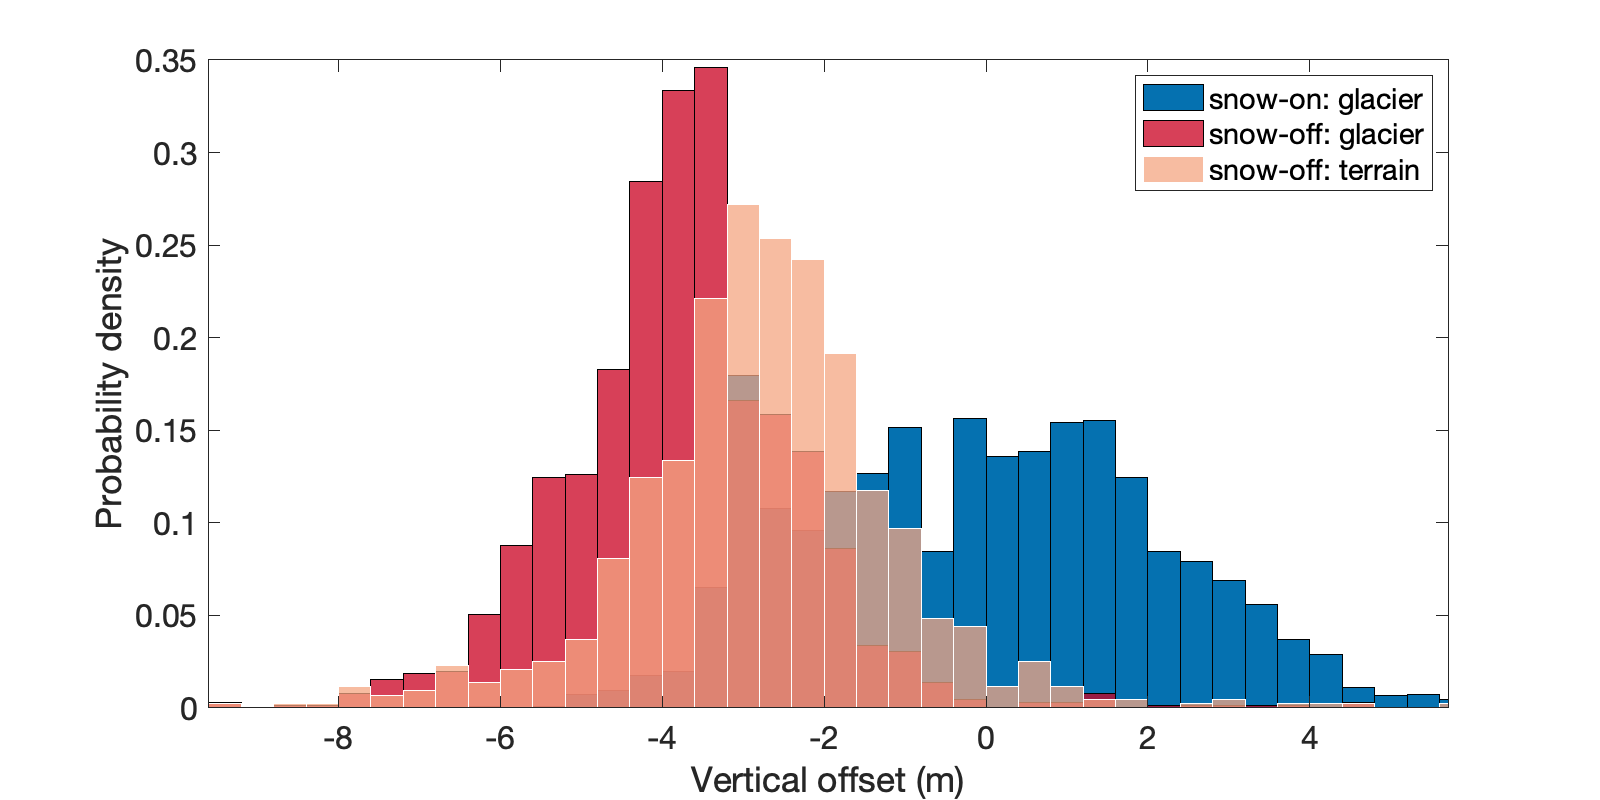

%plot histogram subplots according to year
cd(csv_path);

%specify the histogram bin width
binwidth = 0.4;

%identify snow-on and snow-off data
acc_diff = Tin.differences(Tin.season ~= 3); 
acc_verr = Tin.VerticalErrors(Tin.season ~= 3); 
acc_date = Tin.date(Tin.season ~= 3); 
abl_diff = Tin.differences(Tin.season == 3); abl_diff_land = Tout.differences(Tout.season == 3); 
abl_verr = Tin.VerticalErrors(Tin.season == 3); abl_verr_land = Tout.VerticalErrors(Tout.season == 3); 
abl_date = Tin.date(Tin.season == 3); 
abl_colors = [seas_cmap(2,:); [244,165,130]/255];

%plot the histograms
figure; set(gcf,'position',[50 50 800 400]); clear h;
raw_ss = abs(Tin.slope); raw_as = abs(Tin.aspect);
Tin.differences(raw_ss>90 | raw_as > 360 | isinf(Tin.differences) | abs(Tin.differences) > 100) = NaN;
h(1) = histogram(acc_verr,'Normalization','pdf'); h(1).BinWidth = binwidth; h(1).FaceColor = seas_cmap(1,:); h(1).FaceAlpha = 1;  h(1).EdgeColor = 'k'; hold on;
h(2) = histogram(abl_verr,'Normalization','pdf'); h(2).BinWidth = binwidth; h(2).FaceColor = abl_colors(1,:); h(2).FaceAlpha = 0.75;  h(2).EdgeColor = 'k'; hold on;
h(3) = histogram(abl_verr_land,'Normalization','pdf'); h(3).BinWidth = binwidth; h(3).FaceColor = abl_colors(2,:); h(3).FaceAlpha = 0.75;  h(3).EdgeColor = 'w'; hold on;
set(gca,'fontsize',16,'xlim',[nanmedian(T.VerticalErrors)-3*1.4826*mad(T.VerticalErrors,1) nanmedian(T.VerticalErrors)+3*1.4826*mad(T.VerticalErrors,1)]); 
leg = legend(h,'snow-on: glacier','snow-off: glacier','snow-off: terrain');
xlabel('Vertical offset (m)'); ylabel('Probability density');
saveas(gcf,[figure_path,abbrev,'_ICESat2verterr_histograms.eps'],'epsc');


%histogram subplots according to hydrologic or mass balance year
figure; set(gcf,'position',[50 50 800 1000]);
for i = 1:length(Z)
    subplot(length(Z),1,i); clear h;
    %add vertical lines for the median and MAD
    plot([nanmedian(acc_diff(ceil(acc_date-Z(i).deciyear)==1)) nanmedian(acc_diff(ceil(acc_date-Z(i).deciyear)==1))],[0 1],'-','color',seas_cmap(1,:),'linewidth',3); hold on;
    plot([nanmedian(acc_diff(ceil(acc_date-Z(i).deciyear)==1)) nanmedian(acc_diff(ceil(acc_date-Z(i).deciyear)==1))],[0 1],'-k','linewidth',1); hold on;
    plot([nanmedian(abl_diff(ceil(abl_date-Z(i).deciyear)==1)) nanmedian(abl_diff(ceil(abl_date-Z(i).deciyear)==1))],[0 1],'-','color',seas_cmap(2,:),'linewidth',3); hold on;
    plot([nanmedian(abl_diff(ceil(abl_date-Z(i).deciyear)==1)) nanmedian(abl_diff(ceil(abl_date-Z(i).deciyear)==1))],[0 1],'-k','linewidth',1); hold on;
    for j = [-1 1]
        plot([nanmedian(acc_diff(ceil(acc_date-Z(i).deciyear)==1))+j*mad(acc_diff(ceil(acc_date-Z(i).deciyear)==1),1) nanmedian(acc_diff(ceil(acc_date-Z(i).deciyear)==1))+j*mad(acc_diff(ceil(acc_date-Z(i).deciyear)==1),1)],[0 1],'-k','linewidth',1); hold on;
        plot([nanmedian(acc_diff(ceil(acc_date-Z(i).deciyear)==1))+j*mad(acc_diff(ceil(acc_date-Z(i).deciyear)==1),1) nanmedian(acc_diff(ceil(acc_date-Z(i).deciyear)==1))+j*mad(acc_diff(ceil(acc_date-Z(i).deciyear)==1),1)],[0 1],'--','color',seas_cmap(1,:),'linewidth',1); hold on;
        plot([nanmedian(abl_diff(ceil(abl_date-Z(i).deciyear)==1))+j*mad(abl_diff(ceil(abl_date-Z(i).deciyear)==1),1) nanmedian(abl_diff(ceil(abl_date-Z(i).deciyear)==1))+j*mad(abl_diff(ceil(abl_date-Z(i).deciyear)==1),1)],[0 1],'-k','linewidth',1); hold on;
        plot([nanmedian(abl_diff(ceil(abl_date-Z(i).deciyear)==1))+j*mad(abl_diff(ceil(abl_date-Z(i).deciyear)==1),1) nanmedian(abl_diff(ceil(abl_date-Z(i).deciyear)==1))+j*mad(abl_diff(ceil(abl_date-Z(i).deciyear)==1),1)],[0 1],'--','color',seas_cmap(2,:),'linewidth',1); hold on;
    end
    
    %add histograms
    h(1) = histogram(acc_diff(ceil(acc_date-Z(i).deciyear)==1),'Normalization','pdf'); h(1).BinWidth = binwidth; h(1).FaceColor = seas_cmap(1,:); h(1).FaceAlpha = 1;  h(1).EdgeColor = 'k'; hold on;
    h(2) = histogram(abl_diff(ceil(abl_date-Z(i).deciyear)==1),'Normalization','pdf'); h(2).BinWidth = binwidth; h(2).FaceColor = seas_cmap(2,:); h(2).FaceAlpha = 0.75;  h(2).EdgeColor = 'k'; hold on;
    %specify limits only if necessary!
    set(gca,'fontsize',16,'xlim',[nanmedian(Tin.differences)-3*1.4826*mad(Tin.differences,1) nanmedian(Tin.differences)+3*1.4826*mad(Tin.differences,1)]); xlims = get(gca,'xlim');
    set(gca,'ylim',[0 1]); ylims = get(gca,'ylim');
    
    %display data stats
    if mod(floor(Z(i).deciyear),4) ~= 0
        if i + 1 <= length(Z)
            text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)),...
                [alphabet(i),') ',num2str(floor(Z(i).deciyear)),'/',num2str(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*365,1,'last')),...
                '/',num2str((Z(i).deciyear-floor(Z(i).deciyear))*365-cumdays(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*365,1,'last'))),'-',...
                num2str(floor(Z(i+1).deciyear)),'/',num2str(find(cumdays<=(Z(i+1).deciyear-floor(Z(i+1).deciyear))*365,1,'last')),...
                '/',num2str(ceil((Z(i+1).deciyear-floor(Z(i+1).deciyear))*365-cumdays(find(cumdays<=(Z(i+1).deciyear-floor(Z(i+1).deciyear))*365,1,'last')))-1)],...
                'fontsize', 14)
        else
            text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)),...
                [alphabet(i),') ',num2str(floor(Z(i).deciyear)),'/',num2str(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*365,1,'last')),...
                '/',num2str((Z(i).deciyear-floor(Z(i).deciyear))*365-cumdays(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*365,1,'last'))),'-',...
                num2str(floor(max(T.date))),'/',num2str(find(cumdays<=(max(T.date)-floor(max(T.date)))*365,1,'last')),...
                '/',num2str(ceil((max(T.date)-floor(max(T.date)))*365-cumdays(find(cumdays<=(max(T.date)-floor(max(T.date)))*365,1,'last'))))],...
                'fontsize', 14)
        end
    else
        if i + 1 <= length(Z)
            text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)),...
                [alphabet(i),') ',num2str(floor(Z(i).deciyear)),'/',num2str(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*366,1,'last')),...
                '/',num2str((Z(i).deciyear-floor(Z(i).deciyear))*366-cumdays(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*366,1,'last'))),'-',...
                num2str(floor(Z(i+1).deciyear)),'/',num2str(find(cumdays<=(Z(i+1).deciyear-floor(Z(i+1).deciyear))*365,1,'last')),...
                '/',num2str(ceil((Z(i+1).deciyear-floor(Z(i+1).deciyear))*365-cumdays(find(cumdays<=(Z(i+1).deciyear-floor(Z(i+1).deciyear))*365,1,'last')))-1)],...
                'fontsize', 14)
        else
            text(min(xlims)+0.025*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)),...
                [alphabet(i),') ',num2str(floor(Z(i).deciyear)),'/',num2str(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*366,1,'last')),...
                '/',num2str((Z(i).deciyear-floor(Z(i).deciyear))*366-cumdays(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*366,1,'last'))),'-',...
                num2str(floor(max(T.date))),'/',num2str(find(cumdays<=(max(T.date)-floor(max(T.date)))*365,1,'last')),...
                '/',num2str(ceil((max(T.date)-floor(max(T.date)))*365-cumdays(find(cumdays<=(max(T.date)-floor(max(T.date)))*365,1,'last'))))],...
                'fontsize', 14)
        end
    end
    disp('Data for dates: ')
    alldates = Tin.date(ceil(Tin.date-Z(i).deciyear)==1); alldates = unique(alldates);
    for j = 1:length(alldates)
        if mod(floor(alldates(j)),4) ~= 0
            disp([num2str(floor(alldates(j))),'/',num2str(find(cumdays<=(alldates(j)-floor(alldates(j)))*365,1,'last')),'/',num2str((alldates(j)-floor(alldates(j)))*365-cumdays(find(cumdays<=(alldates(j)-floor(alldates(j)))*365,1,'last')))]);
        else
            disp([num2str(floor(alldates(j))),'/',num2str(find(cumdays<=(alldates(j)-floor(alldates(j)))*366,1,'last')),'/',num2str((alldates(j)-floor(alldates(j)))*366-cumdays(find(cumdays<=(alldates(j)-floor(alldates(j)))*366,1,'last')))]);
        end
    end
    clear alldates;
    
    %statistics on seasonal elevation differences
    disp(['Median +/- MAD elevation residuals relative to: ',num2str(floor(Z(i).deciyear)),'/',num2str(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*365,1,'last')),'/',num2str((Z(i).deciyear-floor(Z(i).deciyear))*365-cumdays(find(cumdays<=(Z(i).deciyear-floor(Z(i).deciyear))*365,1,'last')))])
    fprintf('Snow-on median +/- MAD elevation residuals= %1.3f +/- %1.3f m',nanmedian(acc_diff(ceil(acc_date-Z(i).deciyear)==1)),mad(acc_diff(ceil(acc_date-Z(i).deciyear)==1),1));
    fprintf('Snow-off median +/- MAD elevation residuals= %1.3f +/- %1.3f m',nanmedian(abl_diff(ceil(abl_date-Z(i).deciyear)==1)),mad(abl_diff(ceil(abl_date-Z(i).deciyear)==1),1));
    
end

Data for dates: 


2019/2/24
2019/2/26
2019/5/28
2019/8/25
2019/8/26


Median +/- MAD elevation residuals relative to: 2018/9/12


Snow-on median +/- MAD elevation residuals= 4.376 +/- 1.137 m

Snow-off median +/- MAD elevation residuals= -0.604 +/- 1.054 m

Data for dates: 


2019/11/24


2020/5/24


Median +/- MAD elevation residuals relative to: 2019/9/20


Snow-on median +/- MAD elevation residuals= 1.195 +/- 0.461 m

Snow-off median +/- MAD elevation residuals= NaN +/- NaN m

Data for dates: 


2020/11/24


2021/2/21
2021/5/22
2021/6/20
2021/7/23
2021/8/22


Median +/- MAD elevation residuals relative to: 2020/9/15.2923


Snow-on median +/- MAD elevation residuals= 2.108 +/- 1.886 m

Snow-off median +/- MAD elevation residuals= -0.882 +/- 0.242 m

% leg = legend(h,'summer','autumn','winter','spring');
leg = legend(h,'snow-on','snow-off');
xlabel('Elevation residuals (m)'); ylabel('Probability density');
saveas(gcf,[figure_path,abbrev,'_annual-ICESat2residual_histograms.eps'],'epsc');


%determine whether the on-glacier histograms for each season are
%significantly different from the off-ice summer histogram using the
%two-sample Kolmogorov-Smirnov test (kstest function in Matlab)
disp('Assessing significance of on-glacier elevation residuals wrt coregistration data')

Assessing significance of on-glacier elevation residuals wrt coregistration data


coregdiffs = Tout.differences(Tout.season == coreg_season);
for i = 1:length(Z)
    fprintf('Hydrologic year: %i',floor(Z(i).deciyear))
    %snow-on
    fprintf('number of snow-on observations = %i \n',length(acc_diff(ceil(acc_date-Z(i).deciyear)==1)));
    if sum(~isnan(acc_diff(ceil(acc_date-Z(i).deciyear)==1))) > 0
        acc_sigtest = kstest2(acc_diff(ceil(acc_date-Z(i).deciyear)==1),coregdiffs);
        if acc_sigtest == 1; disp('snow-on = significantly different'); else; disp('snow-on = not significantly different'); end
        clear acc_sigtest;
    end
    %snow-off
    fprintf('number of snow-off observations = %i \n',length(abl_diff(ceil(abl_date-Z(i).deciyear)==1)));
    if sum(~isnan(abl_diff(ceil(abl_date-Z(i).deciyear)==1))) > 0
        abl_sigtest = kstest2(abl_diff(ceil(abl_date-Z(i).deciyear)==1),coregdiffs);
        if abl_sigtest == 1; disp('snow-off = significantly different'); else; disp('snow-off = not significantly different'); end
        clear abl_sigtest;
    end
end

Hydrologic year: 2018

number of snow-on observations = 821 


snow-on = significantly different


number of snow-off observations = 564 


snow-off = significantly different


Hydrologic year: 2019

number of snow-on observations = 532 


snow-on = significantly different


number of snow-off observations = 0 


Hydrologic year: 2020

number of snow-on observations = 1137 


snow-on = significantly different


number of snow-off observations = 387 


snow-off = significantly different


## Plot Histograms of Terrain Parameters

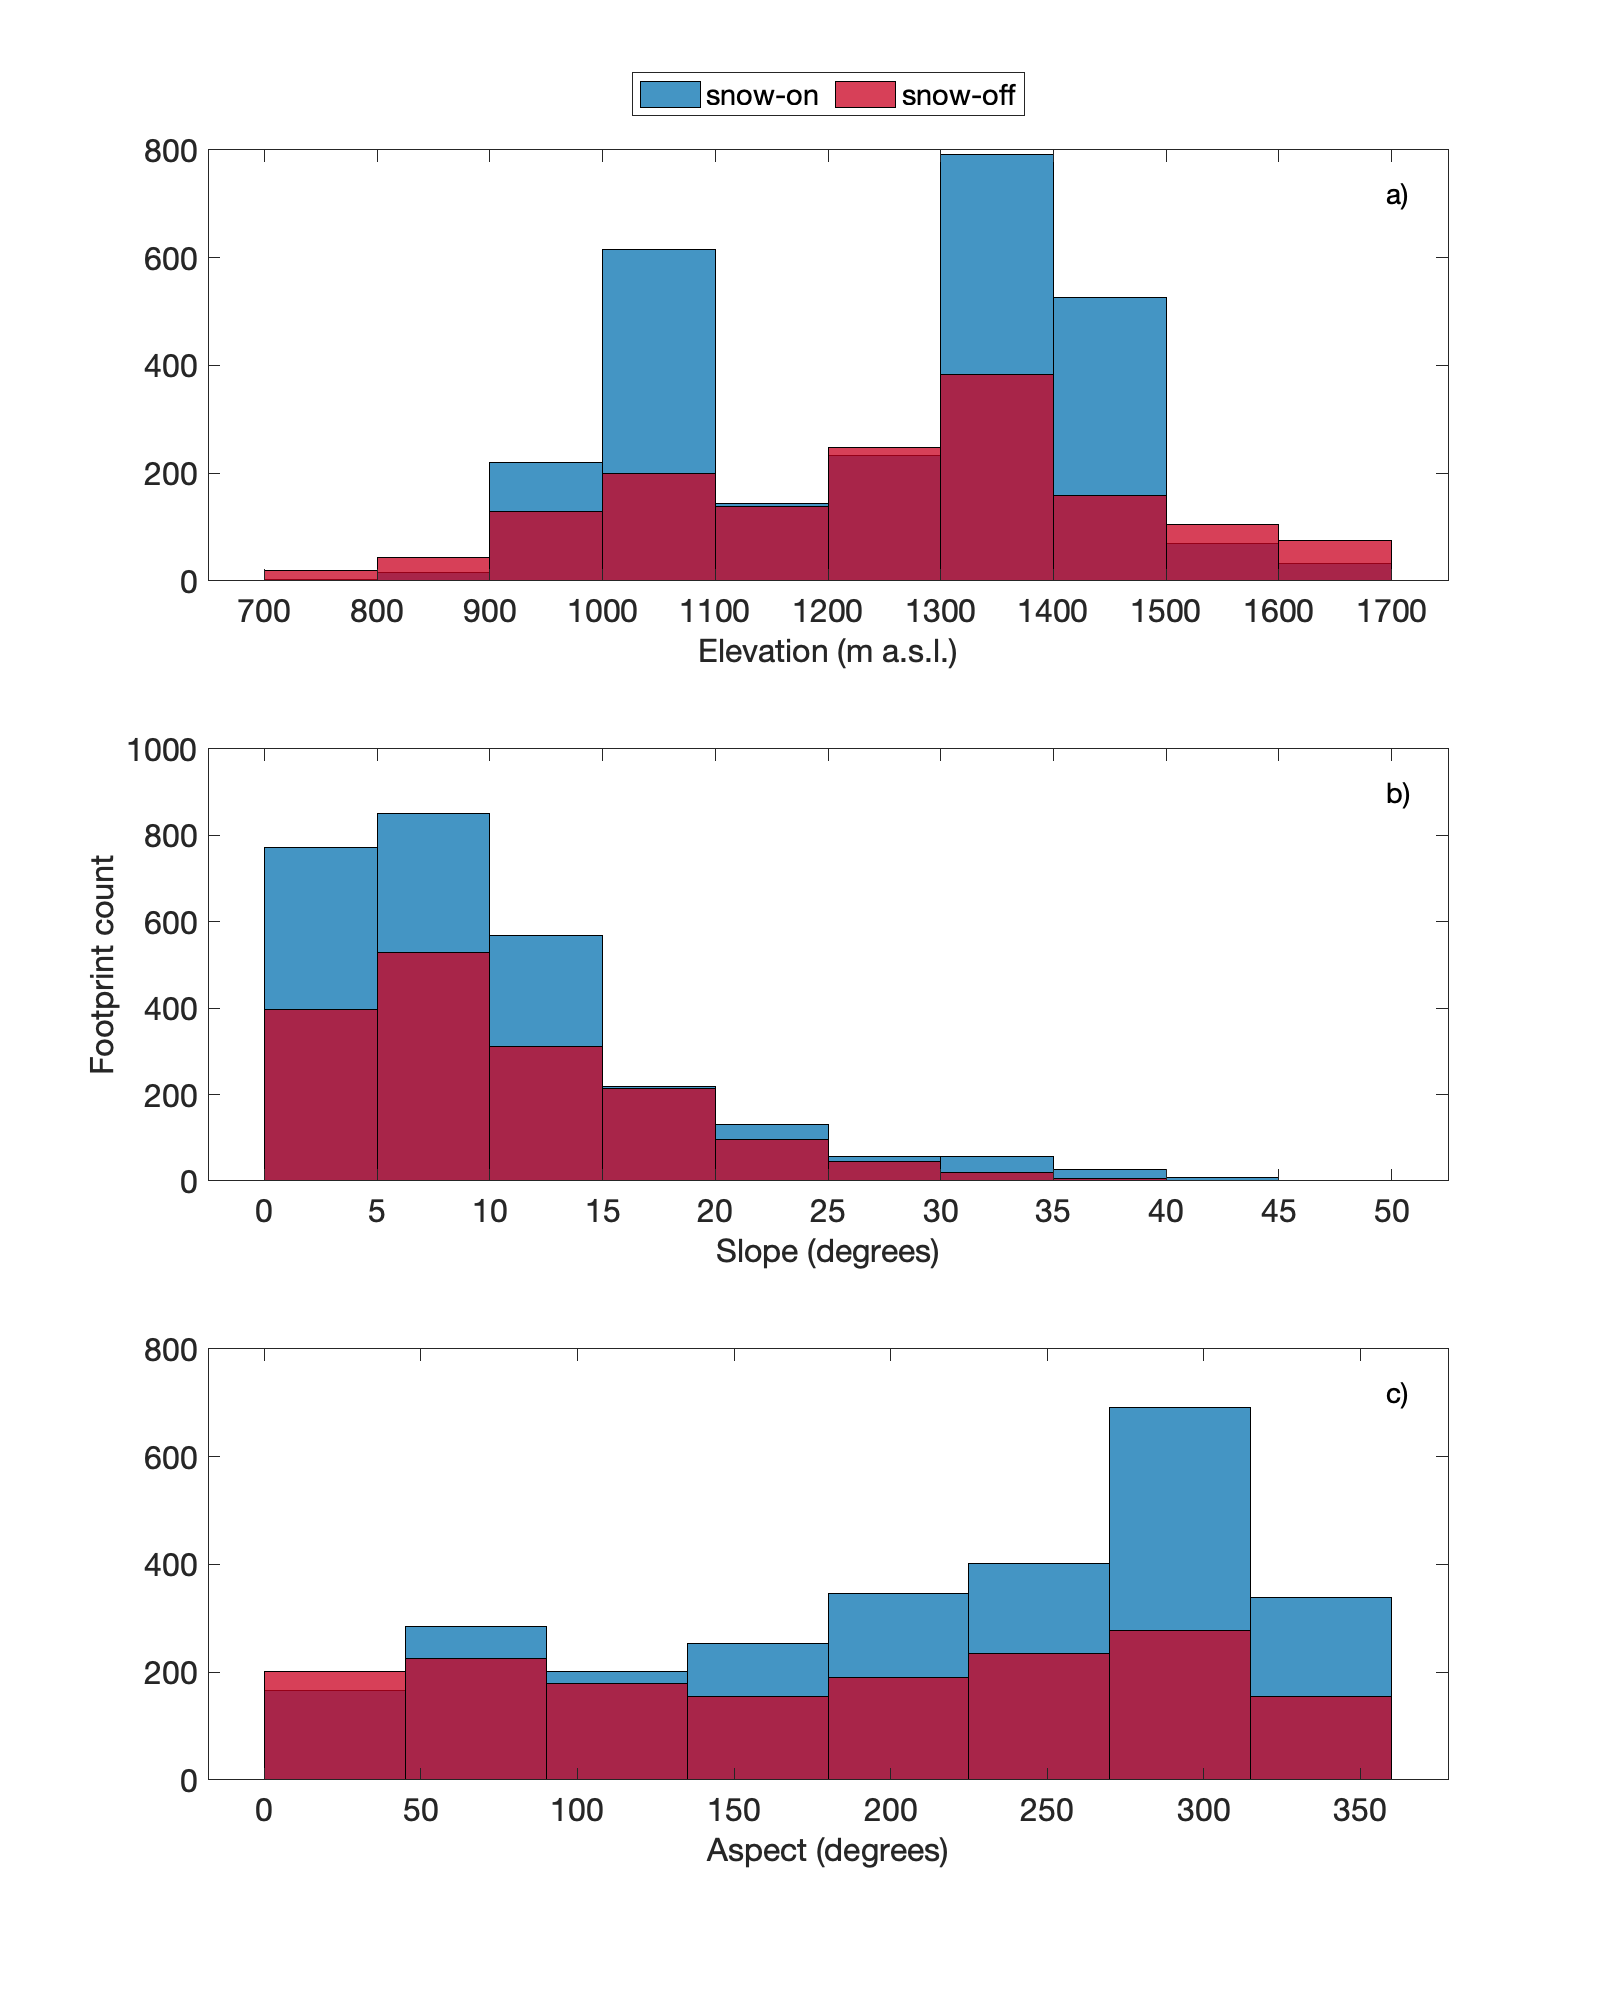

%subplots of seasonal distributions of each terrain parameter to include as
%a supplemental figure to support wonky steep slope & high elevation results (too few observations)

%run previous section to get binwidths
figure; set(gcf,'position',[50 50 800 1000]); clear h;
subplot(3,1,1);
h(1) = histogram(Tin.ReferenceElevation((Tin.season ~= 3))); h(1).BinEdges = elev_binedges; h(1).FaceColor = seas_cmap(1,:); h(1).FaceAlpha = 0.75;  h(1).EdgeColor = 'k'; hold on;
h(2) = histogram(Tin.ReferenceElevation((Tin.season==3))); h(2).BinEdges = elev_binedges; h(2).FaceColor = seas_cmap(2,:); h(2).FaceAlpha = 0.75;  h(2).EdgeColor = 'k'; hold on;
set(gca,'fontsize',16); xlims = get(gca,'xlim'); ylims = get(gca,'ylim');
text(max(xlims)-0.05*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)), 'a) ', 'fontsize', 14);
xlabel('Elevation (m a.s.l.)','fontsize',16); pos = get(gca,'position');
legh = legend(h,'snow-on','snow-off','location','northoutside','orientation','horizontal');
set(gca,'position',pos); clear h pos;
subplot(3,1,2);
h(1) = histogram(Tin.slope((Tin.season ~= 3))); h(1).BinEdges = slope_binedges; h(1).FaceColor = seas_cmap(1,:); h(1).FaceAlpha = 0.75;  h(1).EdgeColor = 'k'; hold on;
h(2) = histogram(Tin.slope((Tin.season==3))); h(2).BinEdges = slope_binedges; h(2).FaceColor = seas_cmap(2,:); h(2).FaceAlpha = 0.75;  h(2).EdgeColor = 'k'; hold on;
set(gca,'fontsize',16); xlims = get(gca,'xlim'); ylims = get(gca,'ylim');
text(max(xlims)-0.05*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)), 'b) ', 'fontsize', 14);
xlabel('Slope (degrees)','fontsize',16);
ylbl = ylabel('Segment count','fontsize',16); %set(ylbl,'position',[ylbl.Position(1) 200 ylbl.Position(3)]);
subplot(3,1,3);
h(1) = histogram(Tin.aspect((Tin.season ~= 3))); h(1).BinEdges = aspect_binedges; h(1).FaceColor = seas_cmap(1,:); h(1).FaceAlpha = 0.75;  h(1).EdgeColor = 'k'; hold on;
h(2) = histogram(Tin.aspect((Tin.season==3))); h(2).BinEdges = aspect_binedges; h(2).FaceColor = seas_cmap(2,:); h(2).FaceAlpha = 0.75;  h(2).EdgeColor = 'k'; hold on;
set(gca,'fontsize',16); xlims = get(gca,'xlim'); ylims = get(gca,'ylim');
text(max(xlims)-0.05*(max(xlims)-min(xlims)),max(ylims)-0.1*(max(ylims)-min(ylims)), 'c) ', 'fontsize', 14);
xlabel('Aspect (degrees)','fontsize',16); 


%save the figure
saveas(gcf,[figure_path,abbrev,'_ICESat2terrain_histograms.eps'],'epsc');

## Create maps of reference elevation datasets

%subplots of elevations
figure; set(gcf,'position',[0 0 400 800]);
subplot(3,1,1);
imagesc(Z(1).x,Z(1).y,Z(1).z); axis xy equal; set(gca,'clim',[400 1400]); hold on; %cbar = colorbar;
cmap = cmocean('thermal'); cmap(1,:) = [1 1 1]; colormap(gca,cmap);
plot(S.X,S.Y,'-w','linewidth',2); hold on;
set(gca,'ylim',[6.6935e6 6.7015e6],'xlim',[3.91e5 3.99e5]);
xlims = get(gca,'xlim'); ylims = get(gca,'ylim');
xticks = get(gca,'xtick'); set(gca,'xtick',[]); yticks = get(gca,'ytick');
set(gca,'fontsize',16,'xticklabel',xticks/1000,'yticklabel',yticks/1000);
pos = get(gca,'position'); set(gca,'position',[pos(1) pos(2) 1.1*pos(3) 1.1*pos(4)]);
text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.05*(max(ylims)-min(ylims)),'a) 2018','fontsize',16);
subplot(3,1,2);
imagesc(Z(2).x,Z(2).y,Z(2).z); axis xy equal; set(gca,'clim',[400 1400]); hold on;
cmap = cmocean('thermal'); cmap(1,:) = [1 1 1]; colormap(gca,cmap);
plot(S.X,S.Y,'-w','linewidth',2); hold on;
set(gca,'ylim',ylims,'xlim',xlims);
set(gca,'fontsize',16,'xtick',[min(xticks):2000:max(xticks)],'xticklabel',[],'yticklabel',yticks/1000);
pos = get(gca,'position'); set(gca,'position',[pos(1) pos(2) 1.1*pos(3) 1.1*pos(4)]);
text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.05*(max(ylims)-min(ylims)),'b) 2019','fontsize',16);
% xlabel('Easting (km)','fontsize',16); ylabel('Northing (km)','fontsize',16);
subplot(3,1,3);
imagesc(Z(3).x,Z(3).y,Z(3).z); axis xy equal; set(gca,'clim',[400 1400]); hold on;
cmap = cmocean('thermal'); cmap(1,:) = [1 1 1]; colormap(gca,cmap);
plot(S.X,S.Y,'-w','linewidth',2); hold on;
set(gca,'ylim',ylims,'xlim',xlims);
set(gca,'fontsize',16,'xtick',[min(xticks):2000:max(xticks)],'xticklabel',xticks/1000,'yticklabel',yticks/1000);
pos = get(gca,'position');
cbar = colorbar; cbar.Label.String = 'elevation (m a.s.l.)'; cbar.Location = 'eastoutside'; cbar.Ticks = [400:200:1400];
set(gca,'position',[pos(1) pos(2) 1.1*pos(3) 1.1*pos(4)]);
text(min(xlims)+0.05*(max(xlims)-min(xlims)),min(ylims)+0.05*(max(ylims)-min(ylims)),'c) 2020','fontsize',16);
xlabel('Easting (km)','fontsize',16); ylabel('Northing (km)','fontsize',16);
% xlabel('Easting (km)','fontsize',16); ylabel('Northing (km)','fontsize',16);
saveas(gcf,[figure_path,abbrev,'_annual-elevations.eps'],'epsc');

## Plot reference elevation change time series as maps & histograms

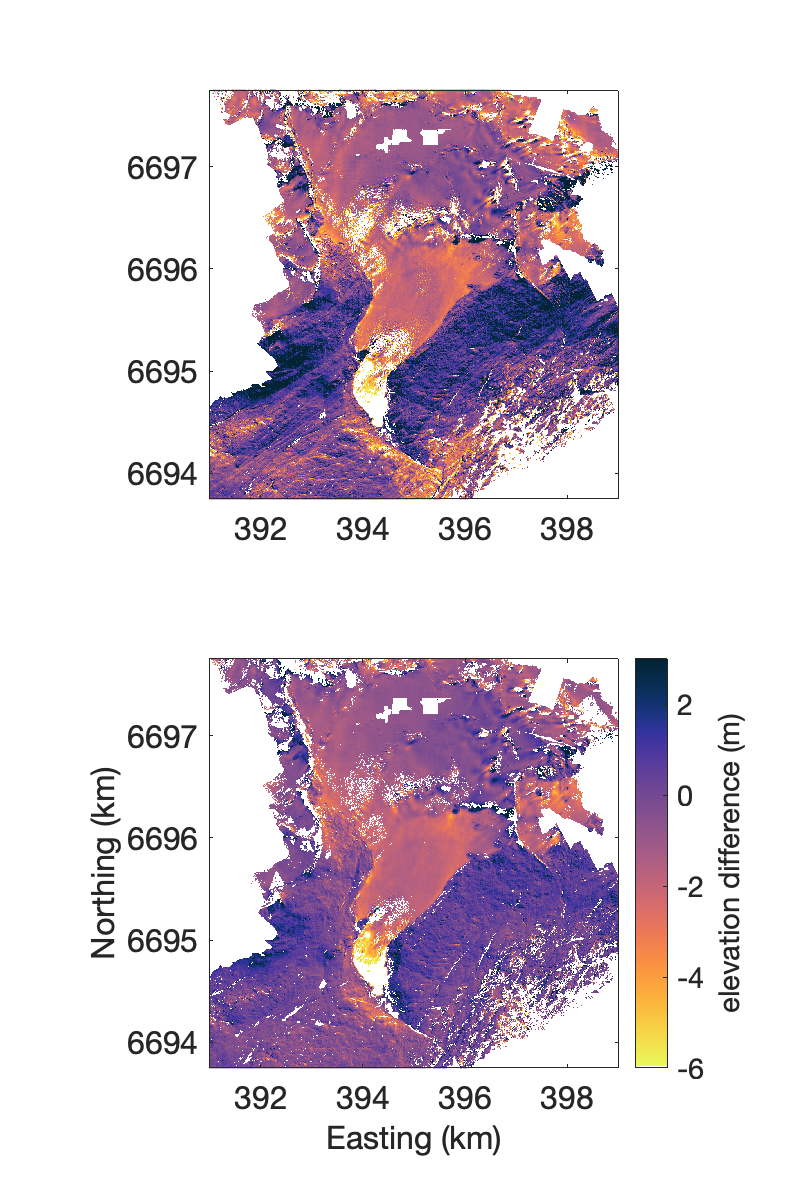

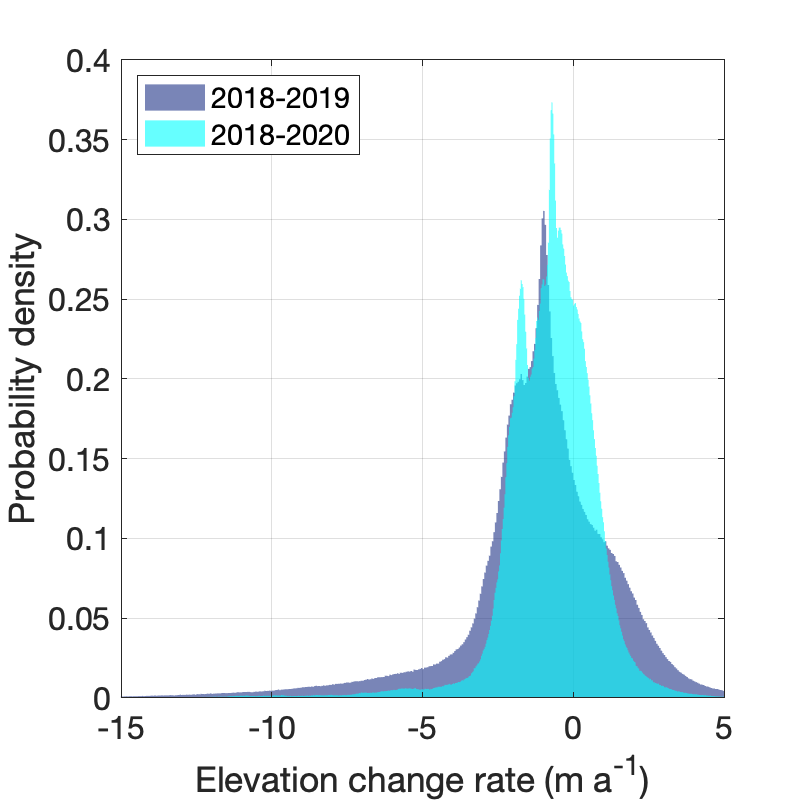

%compute elevation change between years
refDEM = 1; z = Z(refDEM).z;
for i = 1:length(Z)
    if i ~= refDEM
    Z(i).z_interp = interp2(Z(i).xgrid,Z(i).ygrid,Z(i).z,Z(refDEM).xgrid,Z(refDEM).ygrid);
    Z(i).dzdt = (Z(refDEM).z-Z(i).z_interp)./(Z(refDEM).deciyear-Z(i).deciyear);
    Z(i).dzdt(abs(Z(i).dzdt) > 100) = NaN; Z(i).dzdt(Z(i).dzdt == 0) = NaN;
    end
end
pixel_area = Z(refDEM).R.CellExtentInWorldX.*Z(refDEM).R.CellExtentInWorldY;

%create a glacier mask
[in,~] = inpolygon(Z(refDEM).xgrid,Z(refDEM).ygrid,catchment.X(1:end-1),catchment.Y(1:end-1));

%maps of elevation change rates
figure; set(gcf,'position',[0 0 400 600]);
subplot(2,1,1);
imagesc(Z(1).x,Z(1).y,Z(2).dzdt); axis xy equal; set(gca,'clim',[-6 3]);
cmap = cmocean('thermal'); cmap = flipud(cmap); cmap(1,:) = [1 1 1]; colormap(gca,cmap);
set(gca,'ylim',[6.6935e6 6.7015e6],'xlim',[3.91e5 3.99e5]);
xlims = get(gca,'xlim'); ylims = get(gca,'ylim');
xticks = get(gca,'xtick'); set(gca,'xtick',[min(xticks):2000:max(xticks)]);
xticks = get(gca,'xtick'); yticks = get(gca,'ytick');
set(gca,'fontsize',16,'xticklabel',xticks/1000,'yticklabel',yticks/1000);
% xlabel('Easting (km)','fontsize',16); ylabel('Northing (km)','fontsize',16);
subplot(2,1,2);
imagesc(Z(1).x,Z(1).y,Z(3).dzdt); axis xy equal; set(gca,'clim',[-6 3]); pos = get(gca,'position');
cmap = cmocean('thermal'); cmap = flipud(cmap); cmap(1,:) = [1 1 1]; colormap(gca,cmap);
set(gca,'ylim',ylims,'xlim',xlims);
set(gca,'fontsize',16,'xtick',[min(xticks):2000:max(xticks)],'xticklabel',xticks/1000,'yticklabel',yticks/1000);
cbar = colorbar; cbar.Label.String = 'elevation difference (m)';
set(gca,'position',pos);
xlabel('Easting (km)','fontsize',16); ylabel('Northing (km)','fontsize',16);

%create a histogram of elevation change rates
figure; set(gcf,'position',[0 0 400 400]);
h(1) = histogram(Z(2).dzdt(in),'Normalization','pdf','facecolor',[0.1230    0.2031    0.5291],'edgecolor','none'); hold on;
h(2) = histogram(Z(3).dzdt(in),'Normalization','pdf','facecolor','c','edgecolor','none');
set(gca,'xlim',[-15 5],'fontsize',16);
max_count = max([max(h(1).Values) max(h(2).Values)]);
grid on;
leg = legend(h,'2018-2019','2018-2020'); set(leg,'location','northwest');
xlabel('Elevation change rate (m a^{-1})'); ylabel('Probability density');
saveas(gcf,[figure_path,abbrev,'_elevation-change-rate_histograms.eps'],'epsc');


% %elevation change vs elevation
% figure; set(gcf,'position',[0 0 400 400]);
% plot(z(~isnan(z)),Z(2).dzdt(~isnan(z)),'.','markerfacecolor',[0.1230    0.2031    0.5291]); hold on;
% plot(z(~isnan(z)),Z(3).dzdt(~isnan(z)),'.','markerfacecolor','c'); hold on;
% set(gca,'ylim',[-20 20])


## Adjust Elevation Residuals for Emergence/Submergence

%load mean emergence/submergence GPS-based maps from Lucas Zeller and Dan McGrath
cd(root_path); cd('glaciers/Wolverine/MassBalances/Emergence Velocities/GPR/');
[V,R] = readgeoraster('GPR_emergence_mean.tif');
Vx = R.XWorldLimits(1)+0.5*R.CellExtentInWorldX:R.CellExtentInWorldX:R.XWorldLimits(2)-0.5*R.CellExtentInWorldX;
Vy = R.YWorldLimits(2)-0.5*R.CellExtentInWorldY:-R.CellExtentInWorldY:R.YWorldLimits(1)+0.5*R.CellExtentInWorldY;
[Vxgrid,Vygrid] = meshgrid(Vx,Vy);
figure; imagesc(Vx,Vy,V); axis xy equal; cmocean('thermal'); hold on;
plot(Tin.Easting(~isnan(Tin.differences)),Tin.Northing(~isnan(Tin.differences)),'sw','markersize',6); hold on;
plot(Tout.Easting(~isnan(Tout.differences)),Tout.Northing(~isnan(Tout.differences)),'dw','markersize',6); hold on;
    
%interpolate mean vertical velocities to the ICESat-2 footprints
Tin.Vertical_Velocity = interp2(Vxgrid,Vygrid,V,Tin.Easting,Tin.Northing); %velocity in meters/year (negative = submergence = downwards)

%estimate vertical surface motion between DEM & transect acquisition
%assuming constant vertical speeds throughout the year
dt = Tin.date - Tin.DEMdate; dz = (Tin.Vertical_Velocity.*dt);
Tin.differences_adjusted = double(Tin.differences) - double(dz);
plot(Tin.Easting(~isnan(Tin.differences_adjusted)),Tin.Northing(~isnan(Tin.differences_adjusted)),'+y','markersize',6);
plot(Tin.Easting(~isnan(Tin.differences_adjusted) & Tin.season ~= 3),Tin.Northing(~isnan(Tin.differences_adjusted) & Tin.season ~= 3),'xc','markersize',6);
plot(Tin.Easting(~isnan(Tin.differences_adjusted) & Tin.season == 3),Tin.Northing(~isnan(Tin.differences_adjusted) & Tin.season == 3),'xr','markersize',6);

%show some statistics regarding the elevation adjustments for emergence/submergence
fprintf('Snow-on surface elevation changes: median +/- MAD = %4.1f +/- %4.1f \n',nanmedian(dz((Tin.season ~= 3))),mad(dz((Tin.season ~= 3)),1));

Snow-on surface elevation changes: median +/- MAD = -0.2 +/-  0.6 


fprintf('Snow-off surface elevation changes: median +/- MAD = %4.1f +/- %4.1f \n',nanmedian(dz((Tin.season==3))),mad(dz((Tin.season==3)),1));

Snow-off surface elevation changes: median +/- MAD = -0.6 +/-  1.3 


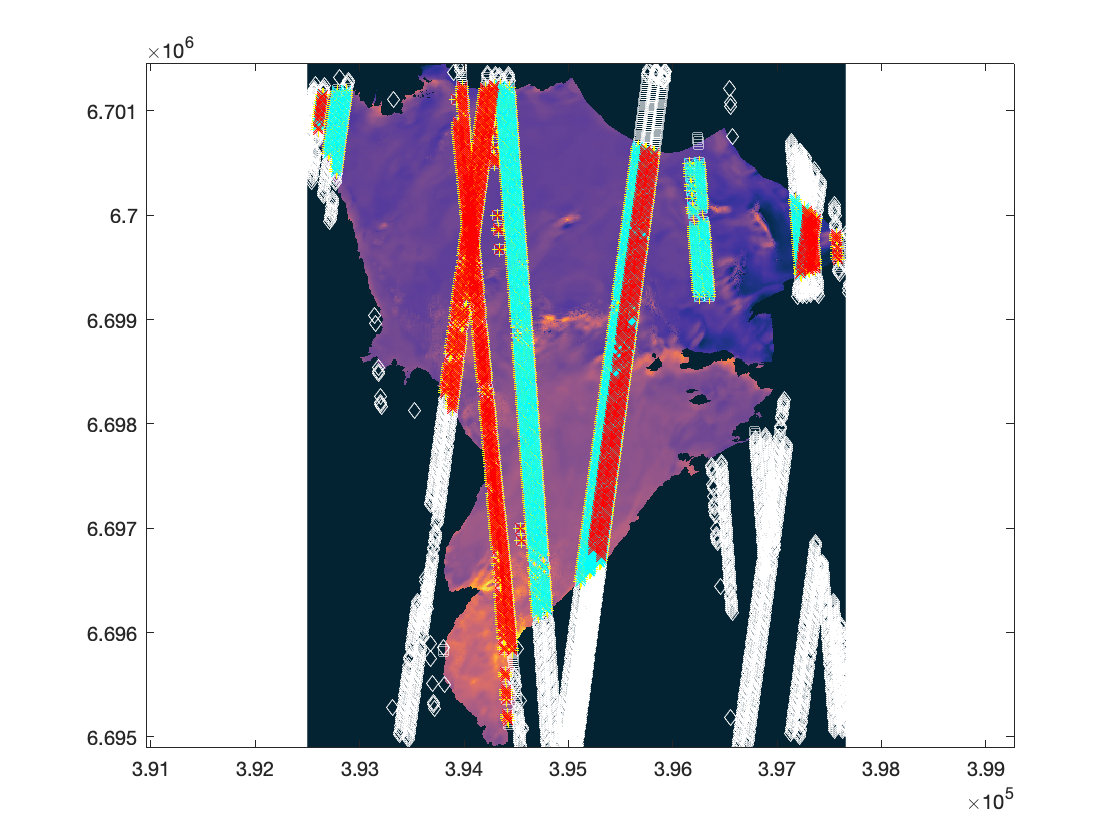

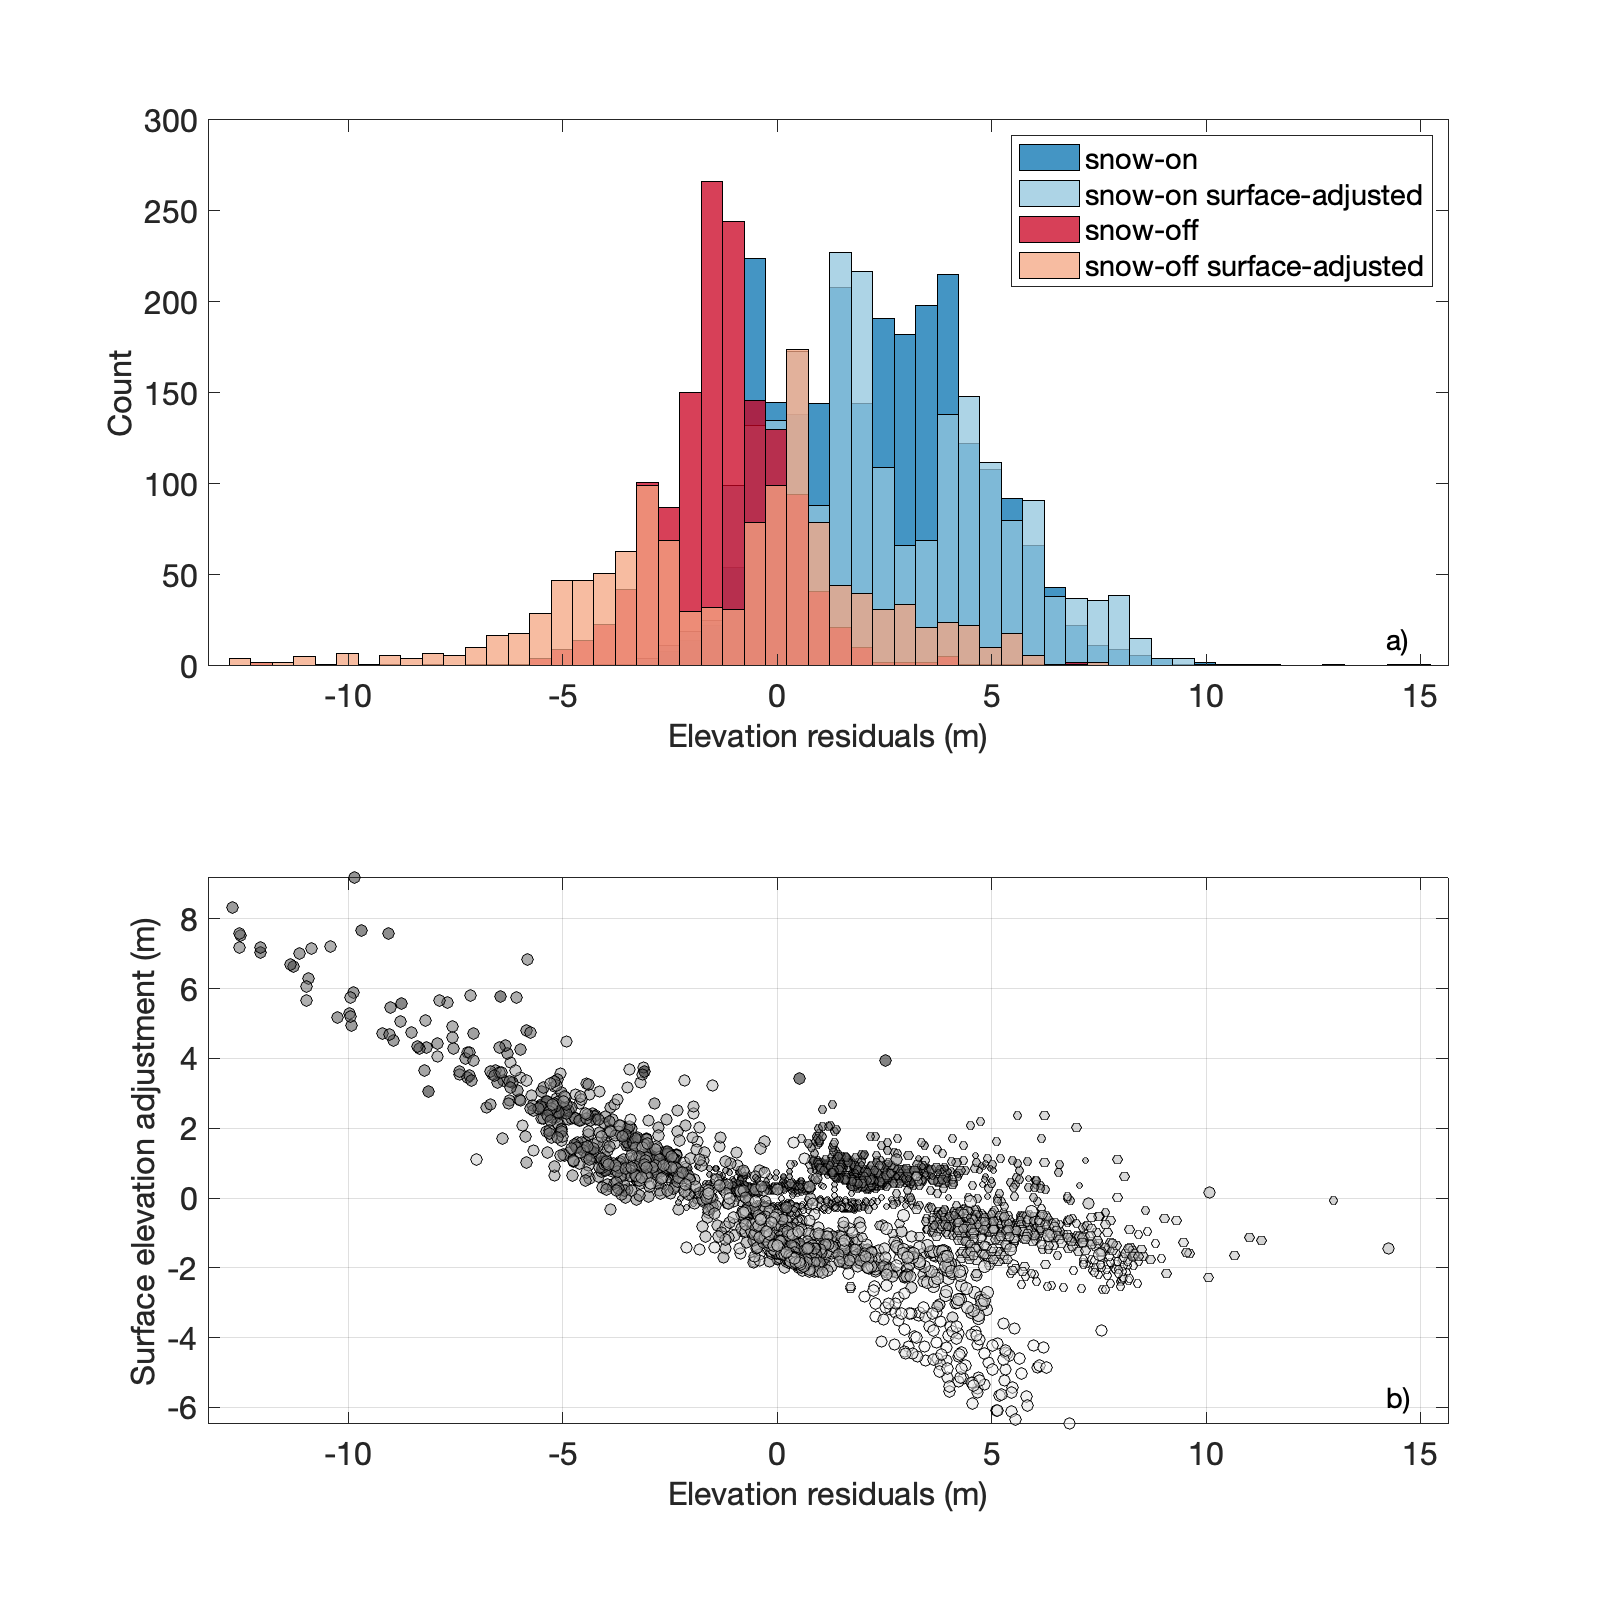


%create color and size maps for scatterplot
VertV_cmap = [];VertV_smap = [];
for j = 1:length(dt)
    cref = round(length(asl_cmap)/range(elev_lims)*(Tin.Elevation(j)-min(elev_lims))); 
    if cref > length(asl_cmap); cref = length(asl_cmap); end
    if isnan(cref) || cref < 1; cref = 1; end
    VertV_cmap(j,:) = asl_cmap(cref,:); VertV_smap(j,:) = 4+(dt(j)*30);
    clear cref;
end

%create figures to visualize the emergence/submergence correction effects
xlims = [nanmedian(Tin.differences_adjusted)-5*1.4826*mad(Tin.differences_adjusted,1) nanmedian(Tin.differences_adjusted)+5*1.4826*mad(Tin.differences_adjusted,1)];
figure; set(gcf,'position',[50 50 800 800]); clear h;
subplot(2,1,1);
h(1) = histogram(Tin.differences(Tin.season ~= 3)); h(1).BinEdges = [xlims(1):0.5:xlims(2)]; h(1).FaceColor = seas_cmap(1,:); h(1).FaceAlpha = 0.75;  h(1).EdgeColor = 'k'; hold on;
h(2) = histogram(Tin.differences_adjusted(Tin.season ~= 3)); h(2).BinEdges = [xlims(1):0.5:xlims(2)]; h(2).FaceColor = [146,197,222]/255; h(2).FaceAlpha = 0.75;  h(2).EdgeColor = 'k'; hold on;
h(3) = histogram(Tin.differences(Tin.season==3)); h(3).BinEdges = [xlims(1):0.5:xlims(2)]; h(3).FaceColor = seas_cmap(2,:); h(3).FaceAlpha = 0.75;  h(3).EdgeColor = 'k'; hold on;
h(4) = histogram(Tin.differences_adjusted(Tin.season==3)); h(4).BinEdges = [xlims(1):0.5:xlims(2)]; h(4).FaceColor = [244,165,130]/255; h(4).FaceAlpha = 0.75;  h(4).EdgeColor = 'k'; hold on;
set(gca,'xlim',xlims,'fontsize',16); ylims = get(gca,'ylim');
legh = legend(h,'snow-on','snow-on surface-adjusted','snow-off','snow-off surface-adjusted');
text(double(max(xlims)-0.05*(range(xlims))),double(min(ylims)+0.05*range(ylims)),'a) ','fontsize',14);
xlabel('Elevation residuals (m)','fontsize',16); ylabel('Count','fontsize',16);
subplot(2,1,2);
scatter(Tin.differences_adjusted,dz,VertV_smap,VertV_cmap,'filled','MarkerEdgeColor','k','MarkerFaceAlpha',0.5); hold on;
set(gca,'xlim',xlims,'ylim',...
    [min(dz(Tin.differences_adjusted>min(xlims) & Tin.differences_adjusted<max(xlims))) max(dz(Tin.differences_adjusted>min(xlims) & Tin.differences_adjusted<max(xlims)))],...
    'fontsize',16,'box','on'); ylims = get(gca,'ylim'); grid on;
text(double(max(xlims)-0.05*(range(xlims))),double(min(ylims)+0.05*range(ylims)),'b) ','fontsize',14);
xlabel('Elevation residuals (m)','fontsize',16); ylabel('Surface elevation adjustment (m)','fontsize',16);

%save!
saveas(gcf,[figure_path,abbrev,'_ICESat2-submergence-adjustment-plots.eps'],'epsc');


%update slope-dependent stats
fprintf('Snow-off SMB info...')

Snow-off SMB info...

soffdiff = Tin.differences_adjusted(Tin.season==3);
soffelev = Tin.Elevation(Tin.season==3);
soffslope = Tin.slope(Tin.season==3);
soffaspect = Tin.aspect(Tin.season==3);
clear soffdiff_elev*
%ELEVATION
for k = 1:length(Z)
    fprintf('Hydrologic year = %i = %i',floor(Z(k).deciyear),ceil(Z(k).deciyear))
    dyear = Tin.date(Tin.season==3) - Z(k).deciyear;
    for j = 1:length(elev_binedges)-1
        soffdiff_elev(j,k) = nanmedian(soffdiff(soffelev>=elev_binedges(j) & soffelev<elev_binedges(j+1) & ceil(dyear)==1));
        soffdiff_elevIQR(j,k) = iqr(soffdiff(soffelev>=elev_binedges(j) & soffelev<elev_binedges(j+1) & ceil(dyear)==1));
        soffdiff_elevMAD(j,k) = mad(soffdiff(soffelev>=elev_binedges(j) & soffelev<elev_binedges(j+1) & ceil(dyear)==1),1);
        soffdiff_elevno(j,k) = length(soffdiff(soffelev>=elev_binedges(j) & soffelev<elev_binedges(j+1) & ceil(dyear)==1));
        soffdiff_elevbin(j,k) = nanmean([elev_binedges(j:j+1)]);
    end
    
    fprintf('Elevation residuals vs elevation:')
    if length(soffdiff_elevbin(~isnan(soffdiff_elev(:,k)),k)) > 2
        [f1,gof1] = fit(soffdiff_elevbin(~isnan(soffdiff_elev(:,k)),k),0.440*soffdiff_elev(~isnan(soffdiff_elev(:,k)),k),'poly1');
        fprintf('SMB gradient in SWE  = %4i mm/100m for 440 kg/m^3 density',100*1000*f1.p1);
        clear *f1;
        [f1,gof1] = fit(soffdiff_elevbin(~isnan(soffdiff_elev(:,k)),k),0.850*soffdiff_elev(~isnan(soffdiff_elev(:,k)),k),'poly1');
        fprintf('SMB gradient in SWE = %4i mm/100m for 850 kg/m^3 density',100*1000*f1.p1);
        fprintf('Bias for min & max elevation bins = [%3.2f,%3.2f]',soffdiff_elev(3,k),soffdiff_elev(end,k));
        fprintf('IQR for min & max elevation bins = [%3.2f,%3.2f]',soffdiff_elevIQR(3,k),soffdiff_elevIQR(end,k));
        fprintf('MAD for min & max elevation bins = [%3.2f,%3.2f]',soffdiff_elevMAD(3,k),soffdiff_elevMAD(end,k));
        clear *f1 ;
    end
    disp(' ')
end

Hydrologic year = 2018 = 2019

Elevation residuals vs elevation:

SMB gradient in SWE  = 6.273416e+02 mm/100m for 440 kg/m^3 density

SMB gradient in SWE = 1.211910e+03 mm/100m for 850 kg/m^3 density

Bias for min & max elevation bins = [-4.01,6.21]

IQR for min & max elevation bins = [1.17,2.41]

MAD for min & max elevation bins = [0.46,0.69]

Hydrologic year = 2019 = 2020

Elevation residuals vs elevation:

Hydrologic year = 2020 = 2021

Elevation residuals vs elevation:

SMB gradient in SWE  = -8.591490e+02 mm/100m for 440 kg/m^3 density

SMB gradient in SWE = -1.659720e+03 mm/100m for 850 kg/m^3 density

Bias for min & max elevation bins = [23.42,3.76]

IQR for min & max elevation bins = [0.00,1.89]

MAD for min & max elevation bins = [0.00,0.94]


%repeat characterization of elevation residuals with respect to terrain
%parameters for the snow on dataset
fprintf('Snow-on SMB info...')

Snow-on SMB info...

sondiff = Tin.differences(Tin.season~=3);
sonelev = Tin.Elevation(Tin.season~=3);
sonslope = Tin.slope(Tin.season~=3);
sonaspect = Tin.aspect(Tin.season~=3);
clear sondiff_elev*;
%ELEVATION
for k = 1:length(Z)
    fprintf('Hydrologic year = %i - %i',floor(Z(k).deciyear),ceil(Z(k).deciyear))
    dyear = Tin.date(Tin.season~=3) - Z(k).deciyear;
    for j = 1:length(elev_binedges)-1
        sondiff_elev(j,k) = nanmedian(sondiff(sonelev>=elev_binedges(j) & sonelev<elev_binedges(j+1) & ceil(dyear)==1));
        sondiff_elevIQR(j,k) = iqr(sondiff(sonelev>=elev_binedges(j) & sonelev<elev_binedges(j+1) & ceil(dyear)==1));
        sondiff_elevMAD(j,k) = mad(sondiff(sonelev>=elev_binedges(j) & sonelev<elev_binedges(j+1) & ceil(dyear)==1),1);
        sondiff_elevno(j,k) = length(sondiff(sonelev>=elev_binedges(j) & sonelev<elev_binedges(j+1) & ceil(dyear)==1));
        sondiff_elevbin(j,k) = nanmean([elev_binedges(j:j+1)]);
    end
    if length(sondiff_elevbin(~isnan(sondiff_elev(:,k)),k)) > 2
        fprintf('Elevation residuals vs elevation:')
        [f1,gof1] = fit(sondiff_elevbin(~isnan(sondiff_elev(:,k)),k),0.440*sondiff_elev(~isnan(sondiff_elev(:,k)),k),'poly1');
        fprintf('SMB gradient in SWE = %4i mm/100m for 440 kg/m^3 density',100*1000*f1.p1);
        clear *f1;
        [f1,gof1] = fit(sondiff_elevbin(~isnan(sondiff_elev(:,k)),k),0.850*sondiff_elev(~isnan(sondiff_elev(:,k)),k),'poly1');
        fprintf('SMB gradient in SWE = %4i mm/100m for 850 kg/m^3 density',100*1000*f1.p1);
        fprintf('Bias for min & max elevation bins = [%3.2f,%3.2f]',sondiff_elev(3,k),sondiff_elev(end,k));
        fprintf('IQR for min & max elevation bins = [%3.2f,%3.2f]',sondiff_elevIQR(3,k),sondiff_elevIQR(end,k));
        fprintf('MAD for min & max elevation bins = [%3.2f,%3.2f]',sondiff_elevMAD(3,k),sondiff_elevMAD(end,k));
        clear *f1;
    end
    disp(' ')
end

Hydrologic year = 2018 - 2019

Elevation residuals vs elevation:

SMB gradient in SWE = 1.488325e+02 mm/100m for 440 kg/m^3 density

SMB gradient in SWE = 2.875174e+02 mm/100m for 850 kg/m^3 density

Bias for min & max elevation bins = [2.69,5.82]

IQR for min & max elevation bins = [0.22,0.44]

MAD for min & max elevation bins = [0.11,0.24]

Hydrologic year = 2019 - 2020

Elevation residuals vs elevation:

SMB gradient in SWE = 3.728647e+01 mm/100m for 440 kg/m^3 density

SMB gradient in SWE = 7.203067e+01 mm/100m for 850 kg/m^3 density

Bias for min & max elevation bins = [0.77,0.80]

IQR for min & max elevation bins = [2.68,1.58]

MAD for min & max elevation bins = [0.32,1.06]

Hydrologic year = 2020 - 2021

Elevation residuals vs elevation:

SMB gradient in SWE = 1.980909e+02 mm/100m for 440 kg/m^3 density

SMB gradient in SWE = 3.826756e+02 mm/100m for 850 kg/m^3 density

Bias for min & max elevation bins = [0.08,NaN]

IQR for min & max elevation bins = [2.64,NaN]

MAD for min & max elevation bins = [0.94,NaN]

## Create Reference ICESat-2 Elevation Residuals Map

disp('Create reference maps: requires that all reference maps are interpolated to the same grid in earlier sections')

%navigate to the csvs
cd_to_csv = ['cd ',csv_path]; eval(cd_to_csv);

%set limits of elevation residuals for color stretching
max_residual = 7; %ceil(max(Tin.differences)) %swap this in if you want to stretch colors over the full range of residuals

%mask-out the portion of the DEM outside of the catchment
for k = 1:length(Z)
    if isempty(Z(k).z_interp)
        zx = Z(k).x; zy = Z(k).y;
        zz(:,:,k) = Z(k).z;
    else
        zz(:,:,k) = Z(k).z_interp;
    end
    zz(zz(:,:,k)<0,k) = NaN;
end
zz_mean = nanmean(zz,3); zz_mean(in==0) = NaN;
xmax = max(max(Z(refDEM).xgrid(in==1))); xmin = min(min(Z(refDEM).xgrid(in==1))); 
ymax = max(max(Z(refDEM).ygrid(in==1))); ymin = min(min(Z(refDEM).ygrid(in==1)));

%set elevation range for maps
elevmap = zz_mean; elevmap(elevmap<min(elev_lims)) = min(elev_lims)+1;

%create a more detailed colorramp for the elevation residuals than the
%11-color import from colorbrewer
resids_cmap = cblind_colors;
while size(resids_cmap,1) < 500
    for j = 1:2*size(resids_cmap,1)
        if mod(j,2) ~= 0
            new_cmap(j,:) = resids_cmap(ceil(j/2),:);
        else
            if j < 2*size(resids_cmap,1)
                new_cmap(j,:) = resids_cmap(ceil(j/2),:) + 0.5*diff(resids_cmap(ceil(j/2):ceil(j/2)+1,:));
            else
                new_cmap(j,:) = resids_cmap(ceil(j/2),:) + 0.5*diff(resids_cmap(ceil(j/2)-1:ceil(j/2),:));
            end
        end
    end
    resids_cmap = new_cmap; clear new_cmap;
    resids_cmap(resids_cmap<0) = 0;
%     disp(size(resids_cmap,1))
end

%create maps w/ & w/o vertical velocity adjustment
for p = 1:2
    %create color matrices for each season
    multiplier = size(resids_cmap,1)/(2*max_residual); %solve for a multiplier to map data values onto a colorramp
    
    %p = 1: use raw differences, p = 2: use vertical velocity-adjusted differences
    if p == 1
        %snow-on season
        acc_diff = [Tin.differences(Tin.season ~= 3); Tout.differences(Tout.season ~= 3)];
        acc_x = [Tin.Easting(Tin.season ~= 3); Tout.Easting(Tout.season ~= 3)];
        acc_y = [Tin.Northing(Tin.season ~= 3); Tout.Northing(Tout.season ~= 3)];
        acc_x(isnan(acc_diff)) = []; acc_y(isnan(acc_diff)) = []; acc_diff(isnan(acc_diff)) = [];
        acc_colormat = ones(length(acc_diff),3);
        for j = 1:length(acc_diff)
            cref = round((acc_diff(j)+max_residual)*multiplier);
            if cref > size(resids_cmap,1); cref = size(resids_cmap,1); elseif cref < 1; cref = 1; end
            acc_colormat(j,:) = resids_cmap(cref,:);
        end
        acc_colormat(acc_colormat<0) = 0;
        %snow-off season
        abl_diff = [Tin.differences(Tin.season == 3); Tout.differences(Tout.season == 3)];
        abl_x = [Tin.Easting(Tin.season == 3); Tout.Easting(Tout.season == 3)];
        abl_y = [Tin.Northing(Tin.season == 3); Tout.Northing(Tout.season == 3)];
        abl_x(isnan(abl_diff)) = []; abl_y(isnan(abl_diff)) = []; abl_diff(isnan(abl_diff)) = [];
        abl_colormat = ones(length(abl_diff),3);
        for j = 1:length(abl_diff)
            cref = round((abl_diff(j)+max_residual)*multiplier);
            if cref > size(resids_cmap,1); cref = size(resids_cmap,1); elseif cref < 1; cref = 1; end
            abl_colormat(j,:) = resids_cmap(cref,:);
        end
        abl_colormat(abl_colormat<0) = 0;
    else
        %snow-on season
        acc_diff = [Tin.differences_adjusted(Tin.season ~= 3); Tout.differences(Tout.season ~= 3)];
        acc_x = [Tin.Easting(Tin.season ~= 3); Tout.Easting(Tout.season ~= 3)];
        acc_y = [Tin.Northing(Tin.season ~= 3); Tout.Northing(Tout.season ~= 3)];
        acc_x(isnan(acc_diff)) = []; acc_y(isnan(acc_diff)) = []; acc_diff(isnan(acc_diff)) = [];
        acc_colormat = ones(length(acc_diff),3);
        for j = 1:length(acc_diff)
            cref = round((acc_diff(j)+max_residual)*multiplier);
            if cref > size(resids_cmap,1); cref = size(resids_cmap,1); elseif cref < 1; cref = 1; end
            acc_colormat(j,:) = resids_cmap(cref,:);
        end
        acc_colormat(acc_colormat<0) = 0;
        %snow-off season
        abl_diff = [Tin.differences_adjusted(Tin.season == 3); Tout.differences(Tout.season == 3)];
        abl_x = [Tin.Easting(Tin.season == 3); Tout.Easting(Tout.season == 3)];
        abl_y = [Tin.Northing(Tin.season == 3); Tout.Northing(Tout.season == 3)];
        abl_x(isnan(abl_diff)) = []; abl_y(isnan(abl_diff)) = []; abl_diff(isnan(abl_diff)) = [];
        abl_colormat = ones(length(abl_diff),3);
        for j = 1:length(abl_diff)
            cref = round((abl_diff(j)+max_residual)*multiplier);
            if cref > size(resids_cmap,1); cref = size(resids_cmap,1); elseif cref < 1; cref = 1; end
            abl_colormat(j,:) = resids_cmap(cref,:);
        end
        abl_colormat(abl_colormat<0) = 0;
    end
    
    
    %create the maps
    figure; set(gcf,'position',[0 0 800 500],'DefaultTextFontSize', 16);
    for i = 1:2
        subplot(1,2,i)
        imagesc(zx,zy,elevmap); axis xy equal; % colormap gray;
        colormap(gca,asl_cmap); set(gca,'clim',elev_lims); hold on; drawnow;
        set(gca,'fontsize',16,'xlim',[xmin xmax],'ylim',[ymin ymax]);
        xticks = get(gca,'xtick'); yticks = get(gca,'ytick');
        subpos = get(gca,'position');
        %plot the shapefile outline
        plot([S.X S.X(1)],[S.Y S.Y(1)],'-y','linewidth',2); hold on;
        
        %set axis labels
        if i == 1
            set(gca,'xticklabels',xticks/1000,'yticklabels',yticks/1000);
        else
            set(gca,'xticklabels',[],'yticklabels',[]);
        end
        if i == 2
            cbar = colorbar; cbar.Label.String = 'elevation (m a.s.l.)';
            set(cbar,'location','eastoutside','orientation','vertical')
        elseif i == 1
            xlabel('Easting (km)','fontsize',16); ylabel('Northing (km)','fontsize',16);
        end
        
        %add data & labels
        if i == 1
            scatter(acc_x,acc_y,17,acc_colormat,'filled','s','MarkerEdgeColor','w','LineWidth',1); hold on;
            scatter(acc_x,acc_y,16,acc_colormat,'filled','s','MarkerEdgeColor','none','LineWidth',0.5); hold on;
            
            %add colorramp
            rectangle('Position',[xmin+150 ymin+100 1350 2*size(resids_cmap,1)+300],'facecolor','w'); %colorramp legend background
            rectangle('Position',[xmin+300 ymin+2*1+200 400 2*size(resids_cmap,1)+80],'facecolor','k');
            for j = 1:length(resids_cmap)
                plot(squeeze([xmin+315; xmin+685]),squeeze([ymin+2*j+250; ymin+2*j+250]),'color',resids_cmap(j,:),'linewidth',1.5); hold on;
            end
            text(xmin+800,ymin+2*size(resids_cmap,1)+250,[num2str(max_residual),' m'],'color','k','fontsize',16);
            text(xmin+800,ymin+0.95*size(resids_cmap,1)+250,'0 m','color','k','fontsize',16);
            text(xmin+800,ymin+250,['-',num2str(max_residual),' m'],'color','k','fontsize',16);
            text(xmax-0.3*(xmax-xmin),ymax-300,'a) snow-on','color',seas_cmap(1,:),'fontsize',16,'BackgroundColor','w');
            
            %enlarge subplot
            set(gca,'position',[subpos(1)-0.03 subpos(2)-0.03 1.1*subpos(3) 1.1*subpos(4)])
            
        elseif i == 2
            scatter(abl_x,abl_y,17,abl_colormat,'filled','s','MarkerEdgeColor','w','LineWidth',1); hold on;
            scatter(abl_x,abl_y,16,abl_colormat,'filled','s','MarkerEdgeColor','none','LineWidth',0.5); hold on;
            text(xmax-0.3*(xmax-xmin),ymax-300,'b) snow-off','color',seas_cmap(2,:),'fontsize',16,'BackgroundColor','w');
            set(gca,'yticklabel',[]);
            %enlarge subplot
            set(gca,'position',[subpos(1)-0.08 subpos(2)-0.03 1.1*subpos(3) 1.1*subpos(4)])
        end
        drawnow; hold on;
    end
    
    %save!
    if p == 1
        saveas(gcf,[figure_path,abbrev,'_ICESat2residuals-map.eps'],'epsc');
    else
        saveas(gcf,[figure_path,abbrev,'_ICESat2residuals-adjusted-map.eps'],'epsc');
    end
    clear acc_* abl_* *colormat;
end
